## TOPIC 13: Plotting in MATLAB

ENGR105, 10/15/20

**An introductory note about data**

As scientists and engineers, you will work a lot with data: acquiring it, processing it, visualizing it. An advantage of MATLAB is that many data visualization capabilities are built into MATLAB. We will start by importing sensor data.

% Load the data we just collected
rawData = load('sensorData5.mat')

rawData = struct with fields:
    Position: [42×6 timetable]


The imported data is an *object*, a data structure. The table that we want can be specified by selecting the `Position` field.

% Timetable containing our collected sensor data
rawData = rawData.Position

rawData = 42×6 timetable
           Timestamp            latitude    longitude    altitude    speed    course     hacc 
    ________________________    ________    _________    ________    _____    ______    ______

    15-Oct-2020 09:03:04.624     39.952      -75.191      13.347     0.462    187.39    35.374
    15-Oct-2020 09:03:05.624     39.952      -75.191       13.07      0.29     203.6    26.742
    15-Oct-2020 09:03:06.624     39.952      -75.191       13.07      0.29     203.6    26.742
    15-Oct-2020 09:03:07.624     39.952      -75.191      13.045     0.245    203.49    21.802
    15-Oct-2020 09:03:08.624     39.952      -75.191      13.053     0.277    209

**Note**: a field is essentially a parameter for the object. This parameter can contain some setting or it can contain useful data.

When working with data, it is **extemely important **to understand what ***class*** (or data type) you are working with.

- `myData` is `timetable` class

- `myData.Timestamp` is `datetime` class

- `myData.speed` is `double` class

- `'hello world'` is `char` class

**Important**: when working with data, part of **STEP 1** (**P**lanning, **p**rep, and **p**seudocode) is always getting your data into the correct format. For now, we will simply convert the above data table into a matrix containing all numbers (of class `double`).

**Note on coordinates systems**: one can convert latitude and longitude differences to distance using knowledge of coordinate systems. For the purposes here, we will use a "rule of thumb" from the [USGS](https://www.usgs.gov/faqs/how-much-distance-does-a-degree-minute-and-second-cover-your-maps?qt-news_science_products=0#qt-news_science_products): At 38 degrees North latitude:

- One degree of **latitude** equals approximately 364,000 feet (69 miles), one minute equals 6,068 feet (1.15 miles), and one-second equals 101 feet. 

- One-degree of **longitude** equals 288,200 feet (54.6 miles), one minute equals 4,800 feet (0.91 mile), and one second equals 80 feet.

% Step 1: convert the Timestamp information into "seconds past start time"
% Convert date time vector into numbers representing the corresponding minutes
t = minute(rawData.Timestamp) + second(rawData.Timestamp)/60;
t = (t - t(1))*60;      % t is now a vector in which entries are in seconds

% Step 2: Convert positional information to relative positions
% Convert both to relative positions
lat_1 = (rawData.latitude - rawData.latitude(1));
long_1 = (rawData.longitude - rawData.longitude(1));

% Both are in units of "degrees" -> convert to units of meters
lat_2 = lat_1*364000*0.3048;
long_2 = long_1*288200*0.3048;

% Convert altitude to relative z position, in meters
alt = rawData.altitude - rawData.altitude(1);

% Step 2: Create data matrix
myData = [t,long_2,lat_2,alt,rawData.speed];
disp(myData)

         0         0         0         0    0.4620
    1.0000   -0.8784   -1.1095   -0.2770    0.2900
    2.0000   -0.8784   -1.1095   -0.2770    0.2900
    3.0000   -0.8784   -2.2189   -0.3020    0.2450
    4.0000   -0.8784   -3.3284   -0.2940    0.2770
    5.0000   -0.8784   -3.3284   -0.3120    0.2750
    6.0010   -0.8784   -3.3284   -0.3090    0.2750
    7.0010   -1.7569   -4.4379   -0.3140    0.2610
    8.0010   -1.7569   -4.4379   -0.3080    0.2570
    9.0010   -1.7569   -4.4379   -0.3060    0.2480
   10.0000   -1.7569   -4.4379   -0.3050    0.2420
   11.1360   -1.7569   -4.4379   -0.3060    0.2370
   26.5430   41.2864  -36.6126   -0.1050         0
   32.5030   44.8001  -38.8315    0.0940         0
   45.7350   64.1257  -53.2547    0.0940         0
   45.7400   64.1257  -53.2547    0.0940         0
   51.9090   39.5295  -44.3789    9.7340         0
   55.3610   35.1373  -44.3789   10.1320         0
   55.7870   45.6785  -52.1452    9.8350         0
   58.1060   47.4354  -57.6925 

**Note**: always include in your script (or function) explicit information about what each row or column of a matrix corresponds to. I do this by commenting out portions of code

% myData(:,1): time, seconds
% myData(:,2): longitude (x value), meters relative to start. 
% Positive x: move east; negative x: move west 
% myData(:,3): latitude (y value), meters relative to start 
% Positive y: move north; negative y: move south
% myData(:,4): altitude (z value), meters relative to start
% myData(:,5): speed, meters/second

### Plotting in 2D

**Helpful resources:**

- **List of plotting functions in MATLAB**

[https://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html](https://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html)

- **Axis settings **

[https://www.mathworks.com/help/matlab/ref/axis.html](https://www.mathworks.com/help/matlab/ref/axis.html)

- The `help` documentation for all of these functions.

#### `plot()` - the "workhorse" plotting function

- `plot()` requires **input vectors of equal length**

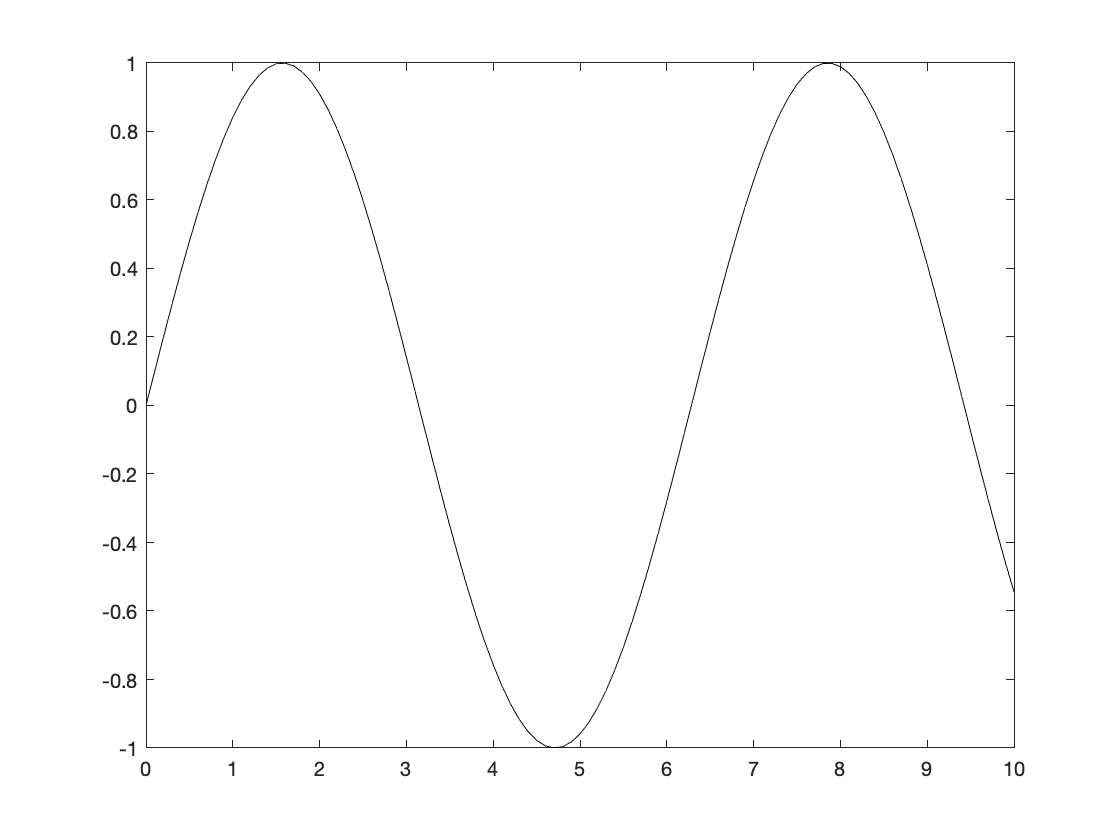

% Independent variable
t = 0:0.1:10;
% Function (dependent variable) is sin(t)
f = sin(t);
% Plot the function: adjust the "line specification" to change the output
plot(t,f,'k-')

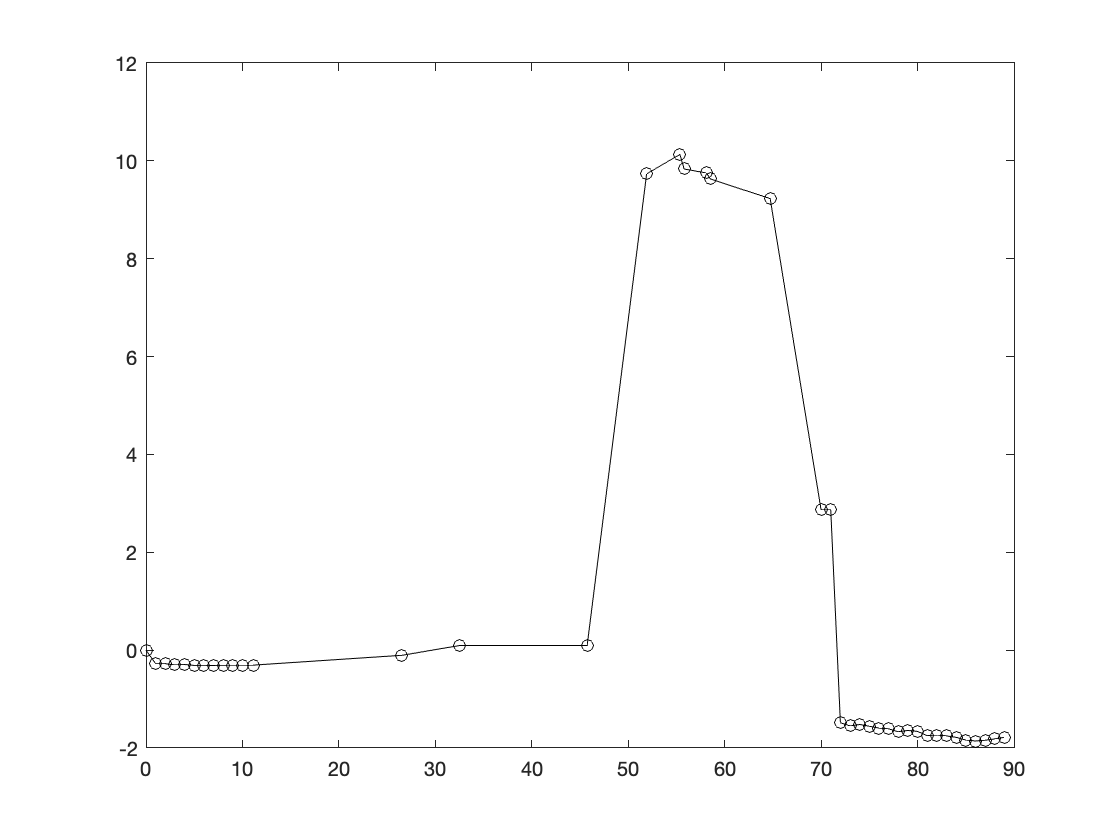

% time
t1 = myData(:,1);
% z position
y1 = myData(:,4);
% Plot the function: adjust the "line specification" to change the output
plot(t1,y1,'ko-');

**Plotting straight lines**. Straight lines can be plotted by specifying as little as two points - the beginning and end of the line

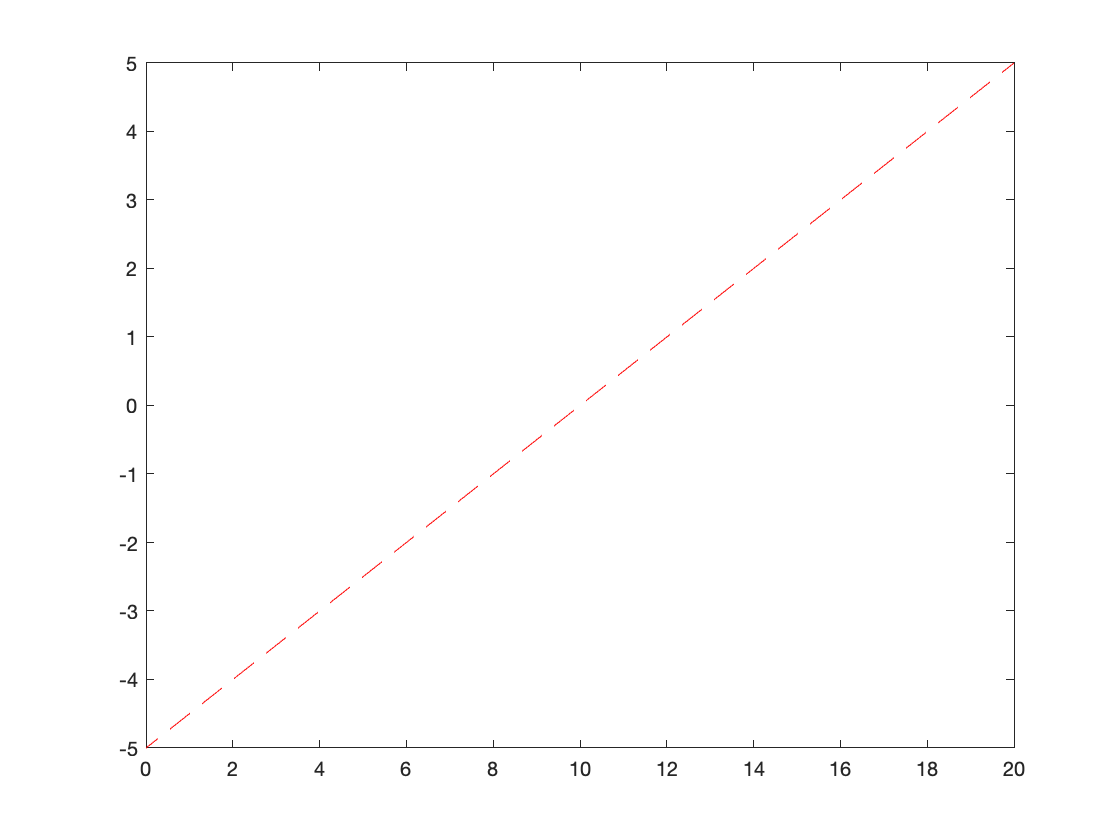

plot([0 20],[-5 5],'r--')

**Plotting one vector**. Most 2D plot commands can be called with a single vector, which is often useful for debugging. 

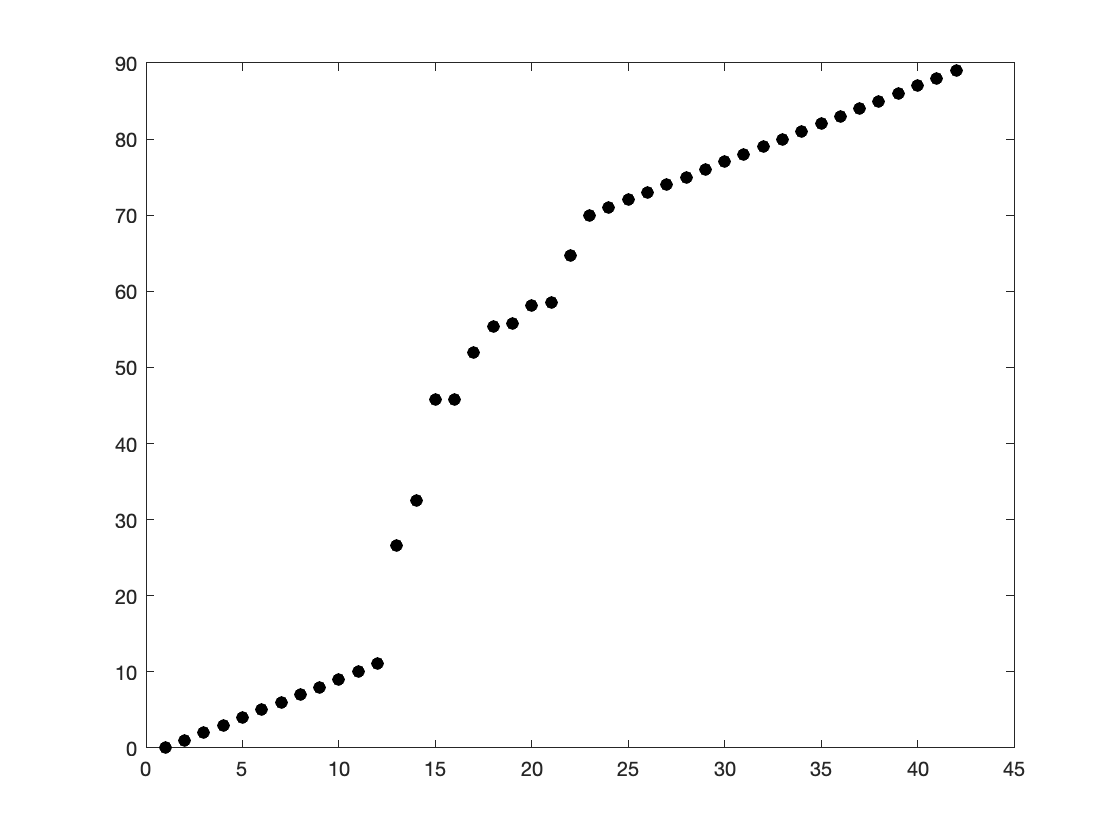

plot(myData(:,1),'ko','MarkerFaceColor','k')

In this case, the x values indicate the **index number**.

#### Overlaying plots

**Using one **`plot`** function call**. Multiple plots may be **overlaid** by **specifying multiple vectors** for most built-in plotting functions. 

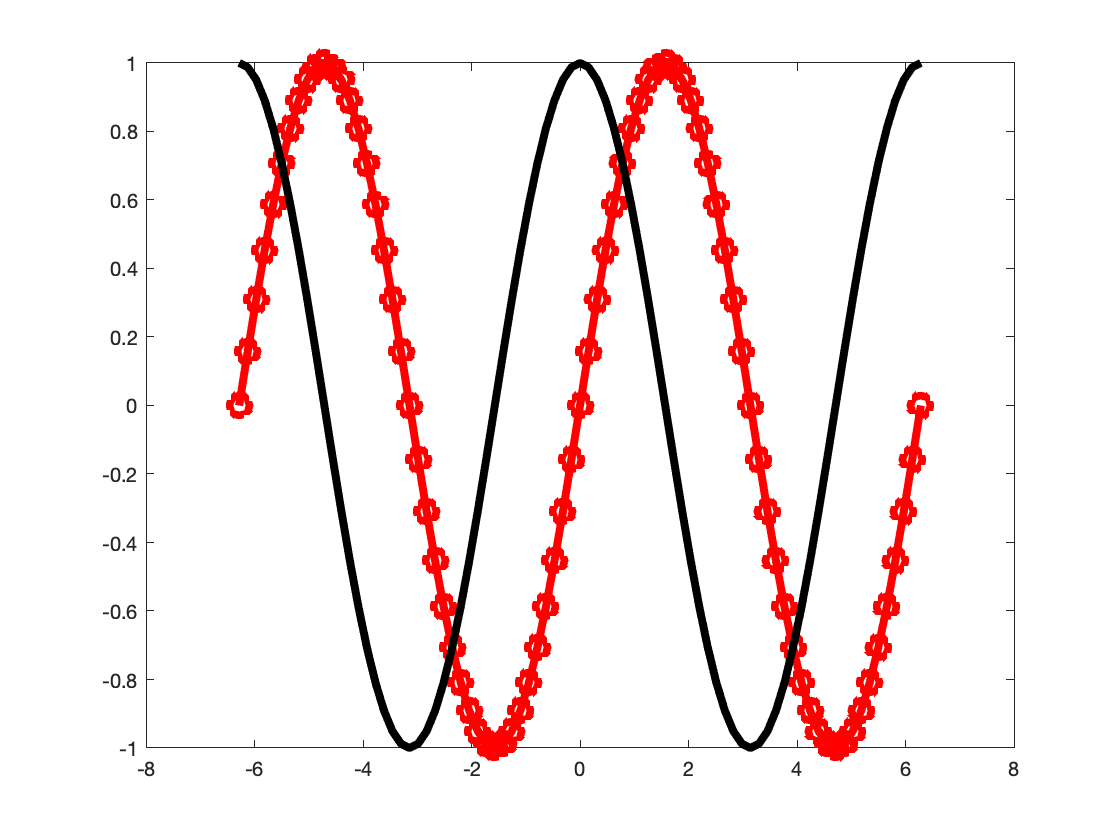

x = -2*pi:pi/20:2*pi;
y1 = sin(x);
y2 = cos(x);
plot(x,y1,'ro-',x,y2,'k-','LineWidth',4,'MarkerSize',10)

Here, the "x" input must be specified for each plot instance. In the above, MATLAB automatically chooses the plotting colors unless otherwise specified. Plot colors may be specified for each vector.

**Note**: line specifications such as `LineWidth` invoked within the plot function will be applied to **all** data series when using this method.

**Using **`hold on`**/**`off`. Multiple plots may also be overlaid by using the `hold on` and `hold off` commands

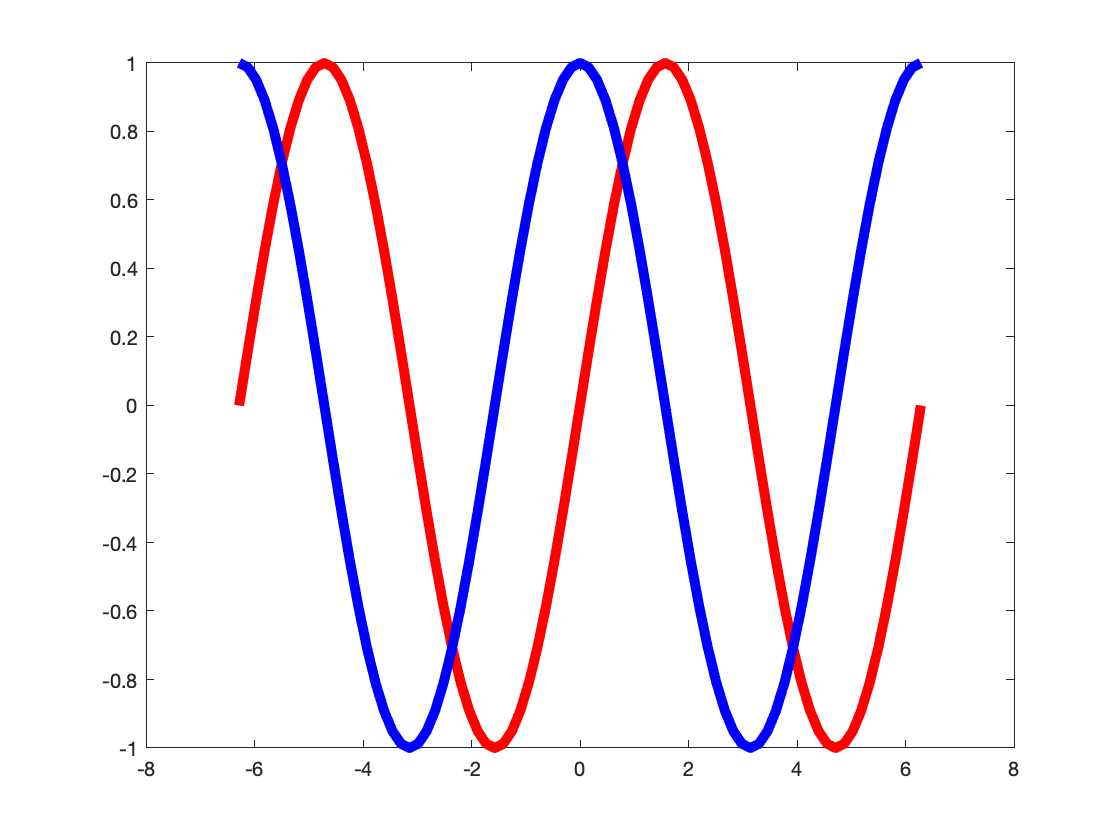

x = -2*pi:pi/20:2*pi;
y1 = sin(x);
y2 = cos(x);
plot(x,y1,'r-','LineWidth', 5)
hold on
plot(x,y2,'b-','LineWidth', 5)
hold off

`hold on` is invoked after the first plot command and indicates that more data will be attributed to the existing axes; `hold off` `"`closes out" `hold on.`

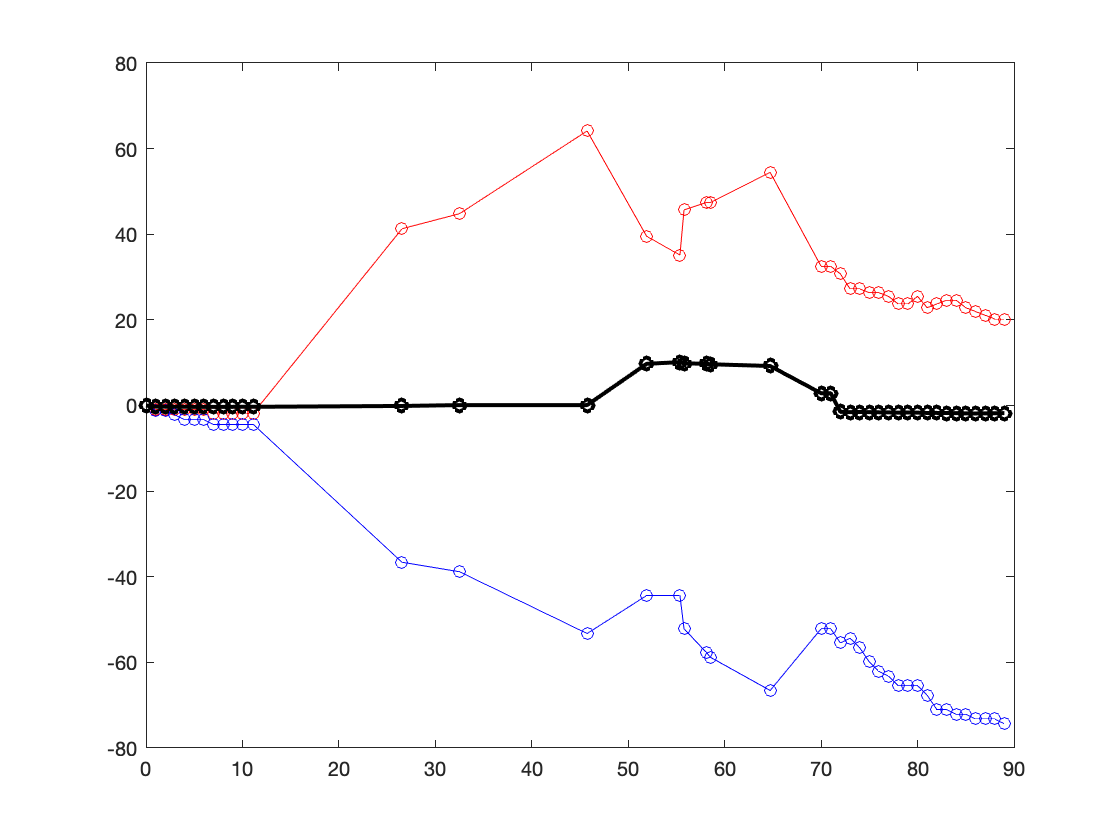

% x position vs. time
plot(myData(:,1), myData(:,2),'ro-');
hold on
% y position vs. time
plot(myData(:,1), myData(:,3),'bo-');
hold on
% z position vs. time
plot(myData(:,1),myData(:,4),'ko-','LineWidth',2)
hold off

**IMPORTANT NOTE**: if you are **not** using a LiveScript file, any additional plots will completely overwrite the axes if you do not use `hold on/off`. hold on is only needed once, though I often call it after every plot for clarity.

#### Specifying plot attributes inline

The canonical plot call is:

**Line specifiers**

- Line style: solid, dash, dot, dash-dot

- Line color: red, green, blue, cyan, etc.

- Marker: plus, circle, asterisk, etc.

**Property names**

- LineWidth

- MarkerSize

- MarkerEdgeColor

- MarkerFaceColor

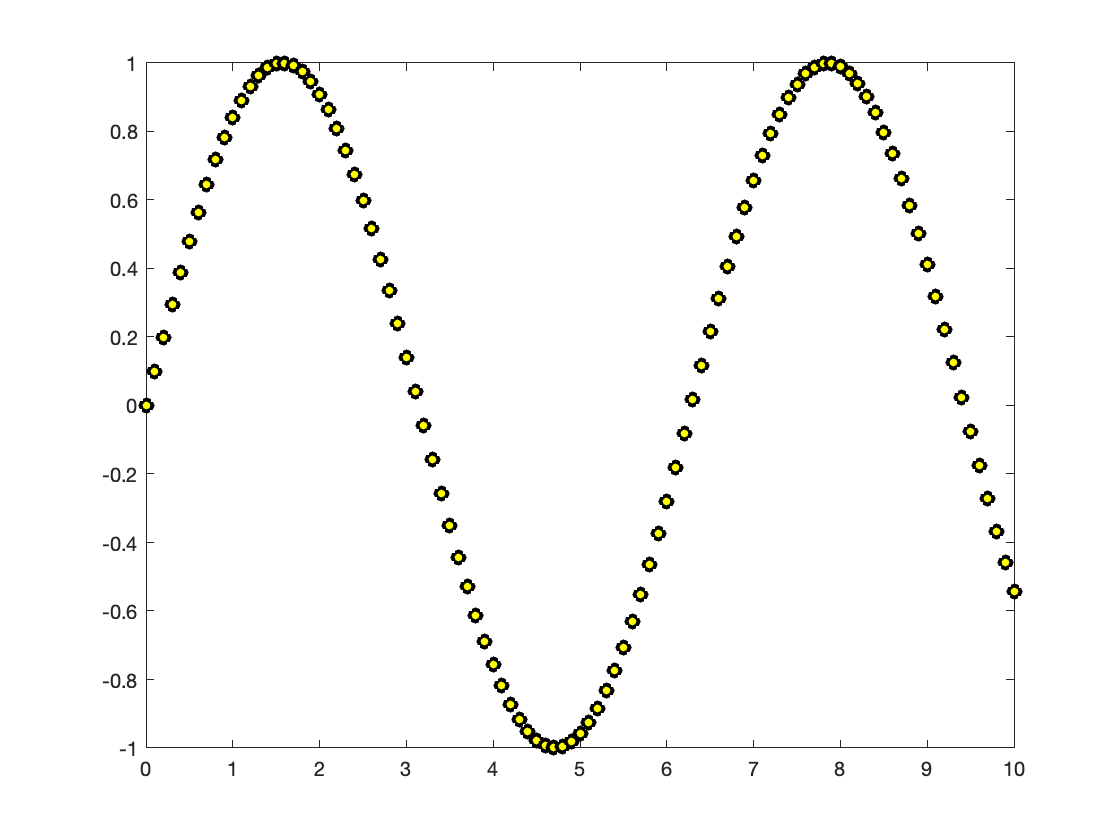

% Independent variable
t = 0:.1:10;
% Function (dependent variable) is sin(t)
f = sin(t);
% Plot the function: adjust the "line specification" to change the output
plot(t,f,'ko','MarkerFaceColor','y','LineWidth',2)

**Note**: the default plot attributes are blue lines, though this can be changed by adjusting the above inputs. Please see the **help** documentation for `plot` and adjust the above plot.

Can you produce the above with:

- Red circles 

- Red circles with lines between markers

- Black circles with connected lines

- Green dots

- Magenta circles with dashed lines between markers

- Black plot line set to a 10 pt width

- Circles with a green face color, red edge color, and 2 pt edge width

#### Colors

MATLAB includes many predefined colors:

- r = Red

- g = Green

- b = Blue

- c = Cyan

- m = Magenta

- y = Yellow

- k = Black

- w = White

Colors may also be specified using the `Color `(or other appropriate) property and specifying the **3-digit RGB color set.**

- RGB colors typically range from 0 to 255 in most computer systems (languages), however, **MATLAB takes in color values rescaled from 0 to 1.**

**Example**. Consider Penn blue (RGB color code 1, 37, 10) and red (RGB color code 149, 0, 26)

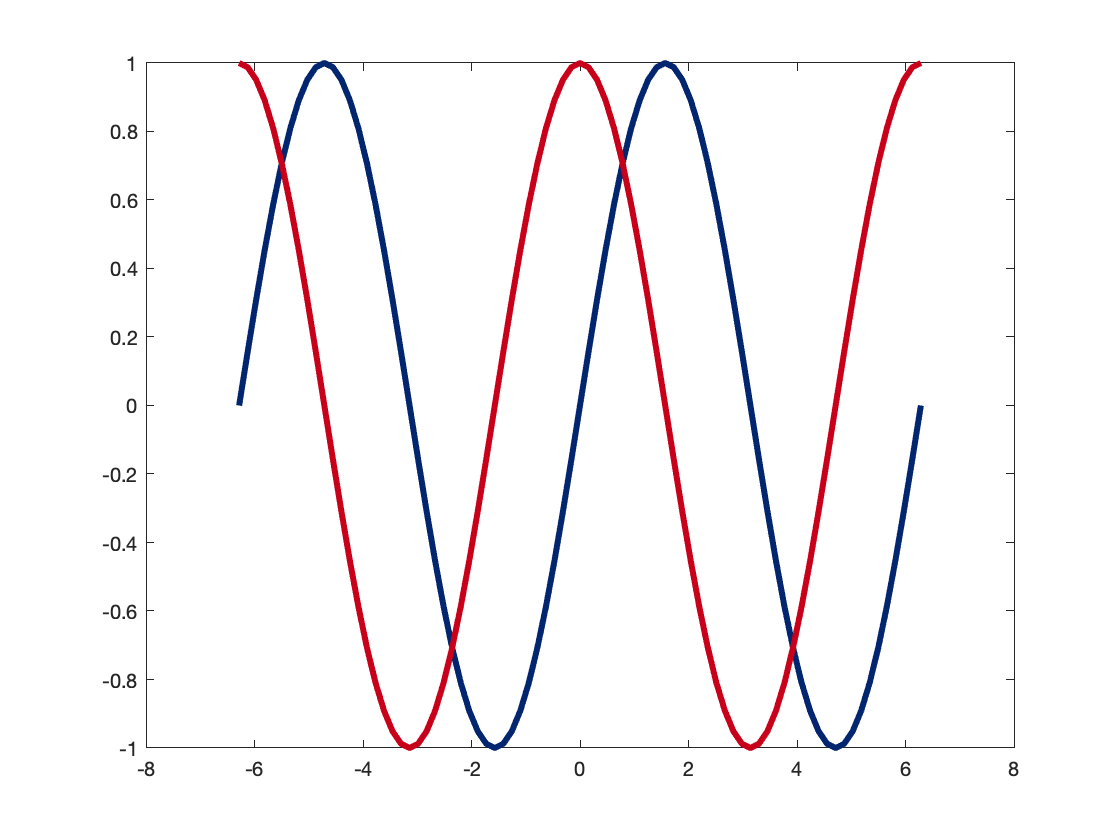

% x vector
x = -2*pi:pi/20:2*pi;
% Two different y functions
y1 = sin(x);
y2 = cos(x);
plot(x,y1,'Color',[1,37,110]./255,'LineWidth',3);
hold on
plot(x,y2,'Color',[200,0,26]./255,'LineWidth',3);
hold off

#### Basic axis formatting

**Consider our example data** -- we want to view our path, only considering motion in the x/y.

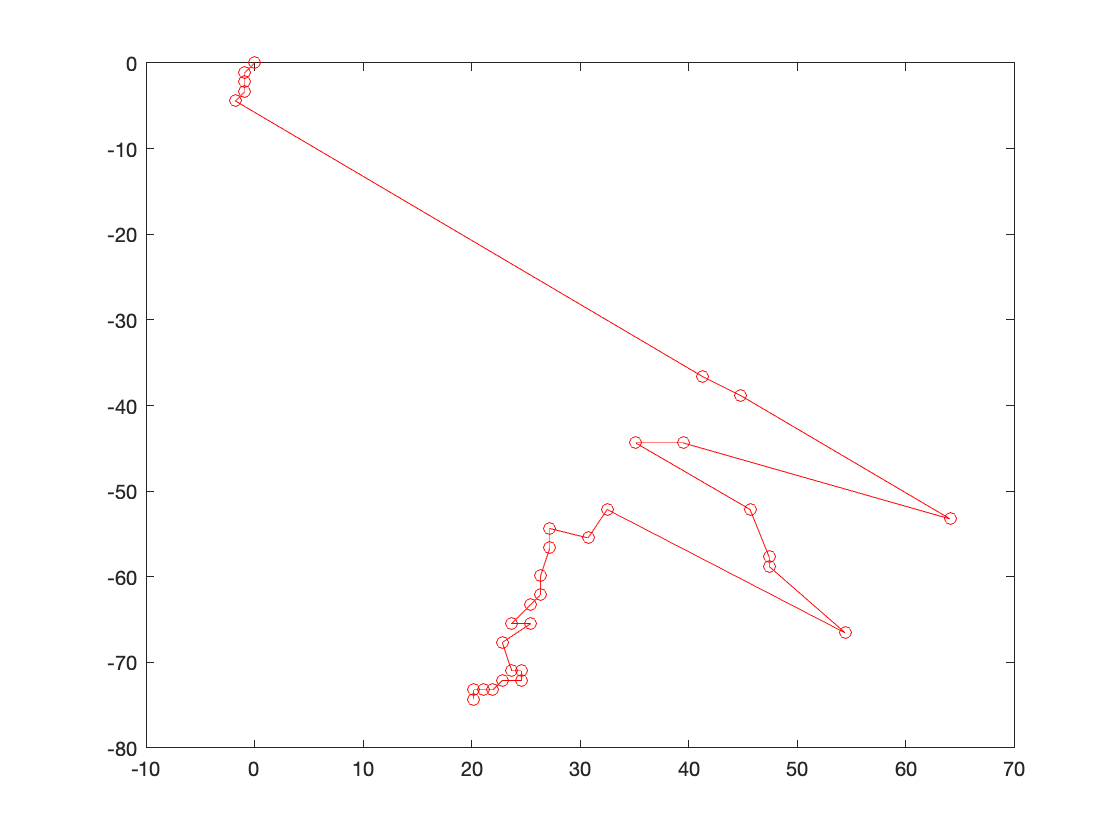

% x position vs. y position
plot(myData(:,2), myData(:,3),'ro-')

- A specific **domain and range** may be specified using `xlim` or `ylim`

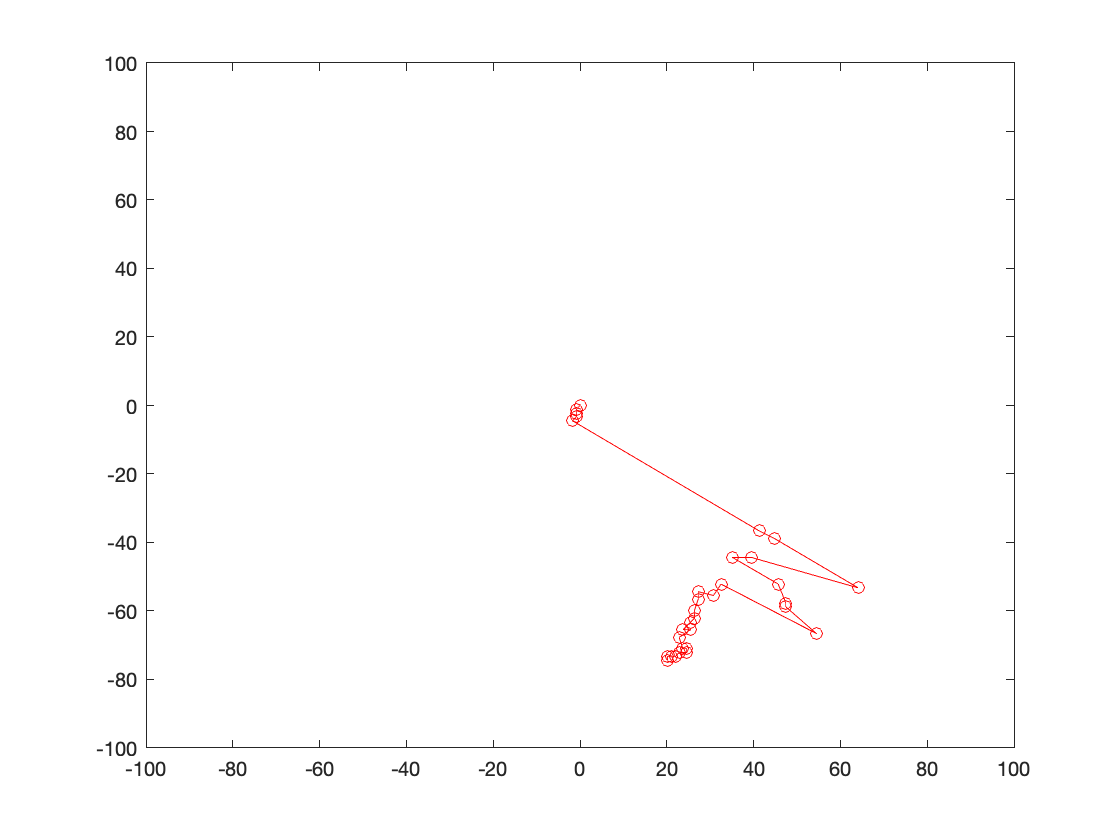

xlim([-100,100]) % set x limit
ylim([-100,100]) % set y limit

- The `axis` command offers many predefined axis scaling/sizing operations

Useful documentation: [https://www.mathworks.com/help/matlab/ref/axis.html](https://www.mathworks.com/help/matlab/ref/axis.html)

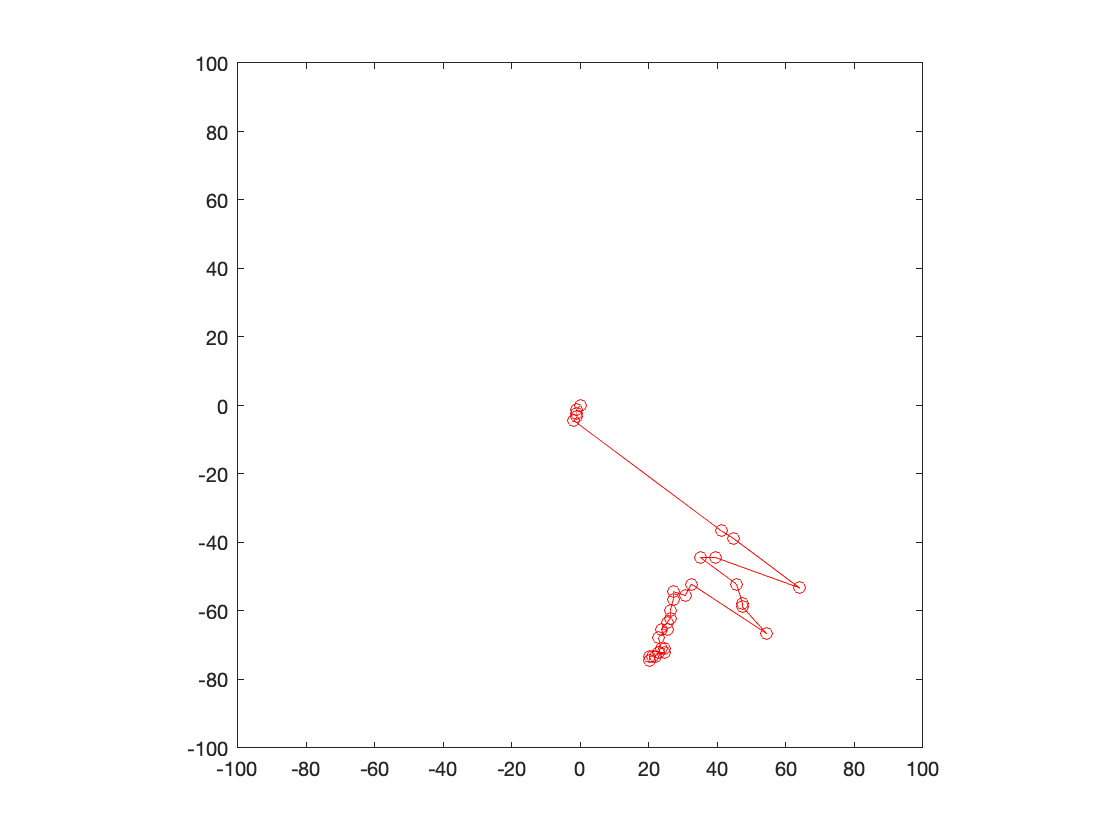

axis square %change shape of axis

**Note**: specifying a parameter like this operates on the previous plot. Information about the previous plot is stored as the** current axis** and **current figure**.

- **Legends** may be added and the position of the legend specified

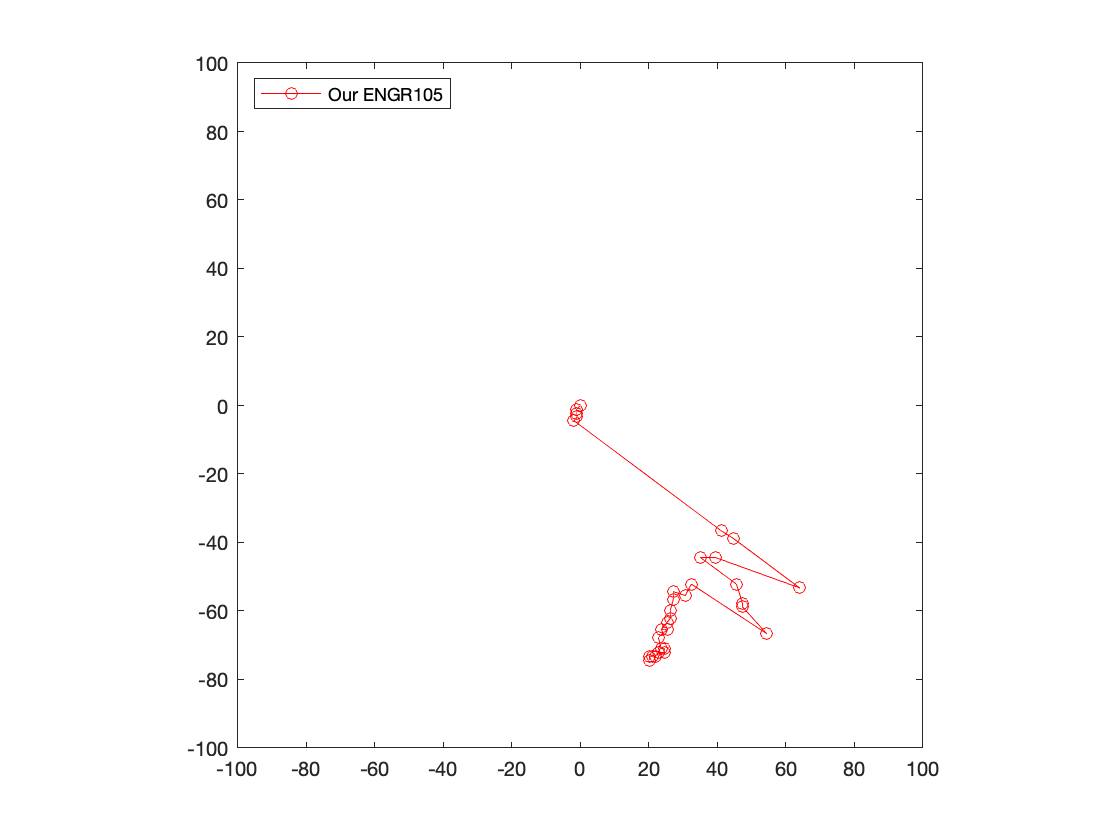

legend('Our ENGR105', 'Location', 'NorthWest');

- **Axis labels and titles** may be placed on the graph

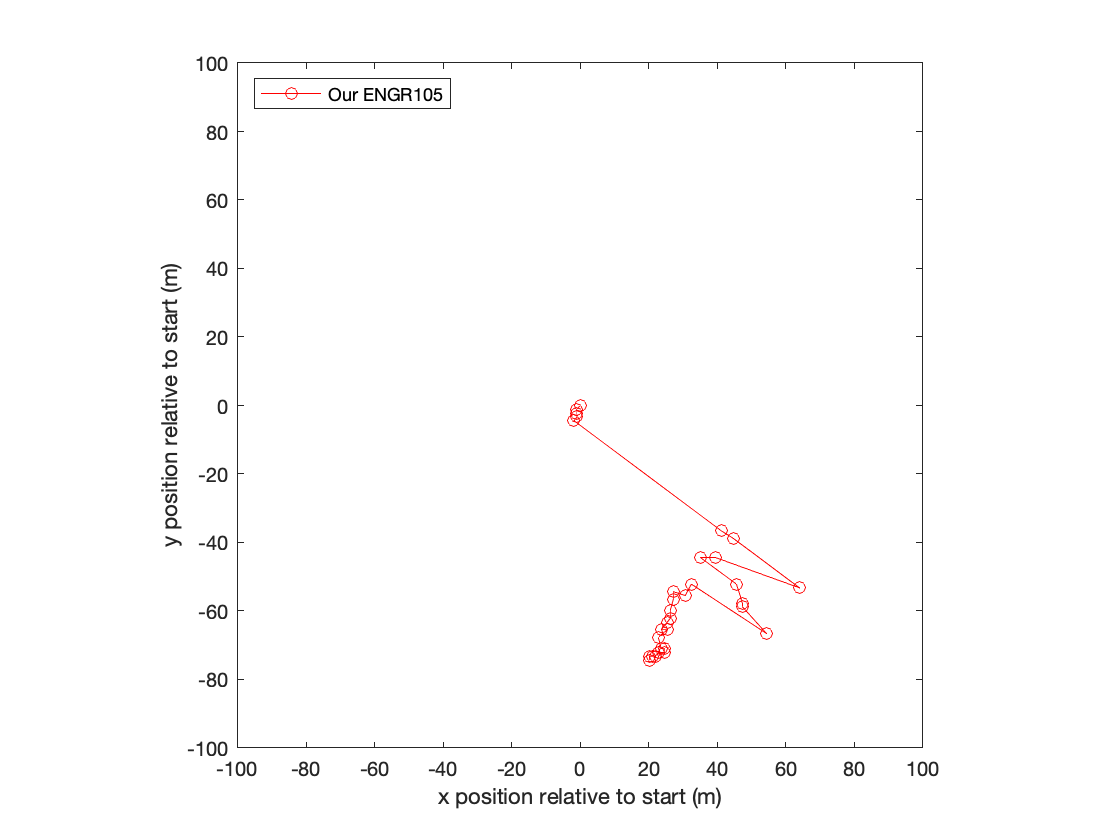

xlabel('x position relative to start (m)')
ylabel('y position relative to start (m)')

- We can add a **title**

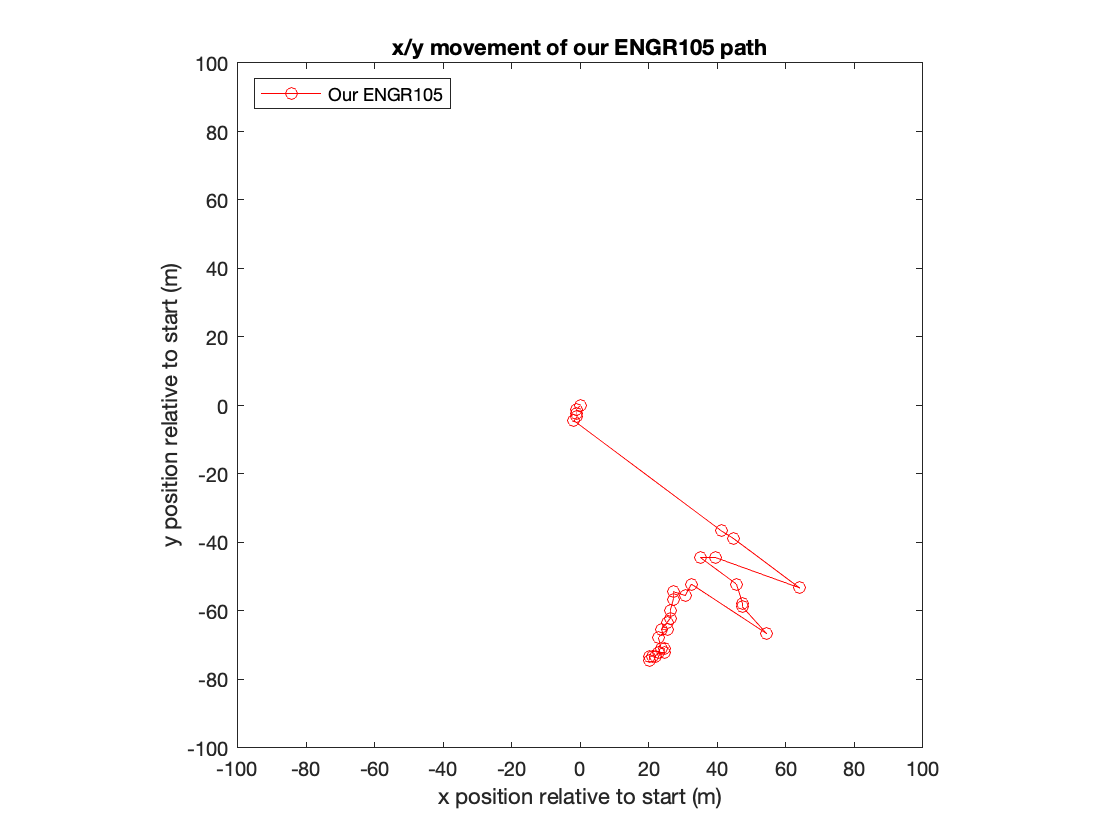

title('x/y movement of our ENGR105 path')

- **Text may be placed on a plot** using the `text` command

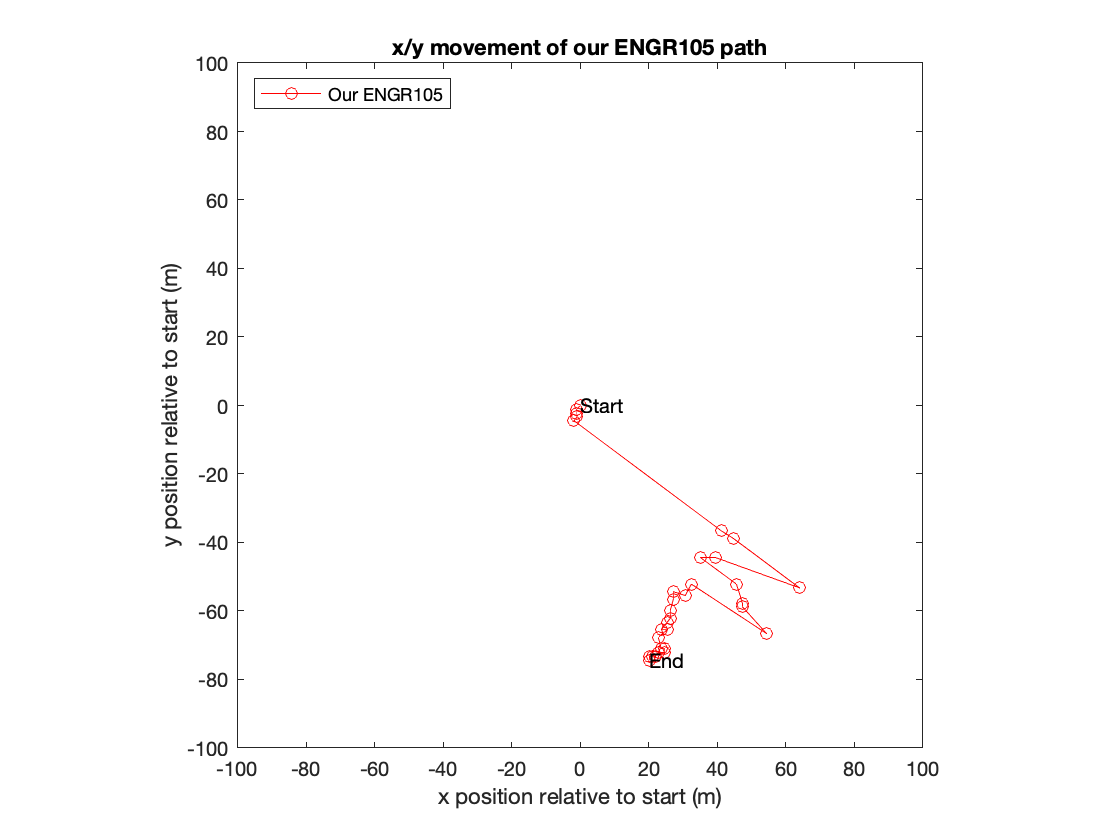

text(myData(1,2), myData(1,3), 'Start')
text(myData(end,2), myData(end,3), 'End')

#### Important note regarding LiveScript files

We are using LiveScript files because these are a really convenient way to combine text and code, ultimately because we want these lecture notes to be an accessible resource for you.

However, when plotting in a `.mlx` file, all figures are embedded in the document (which is what we want). When you are working with a script file (`.m`) or at the command line, figures will "pop up" when called. **The following code will create a plot in a new figure window.**

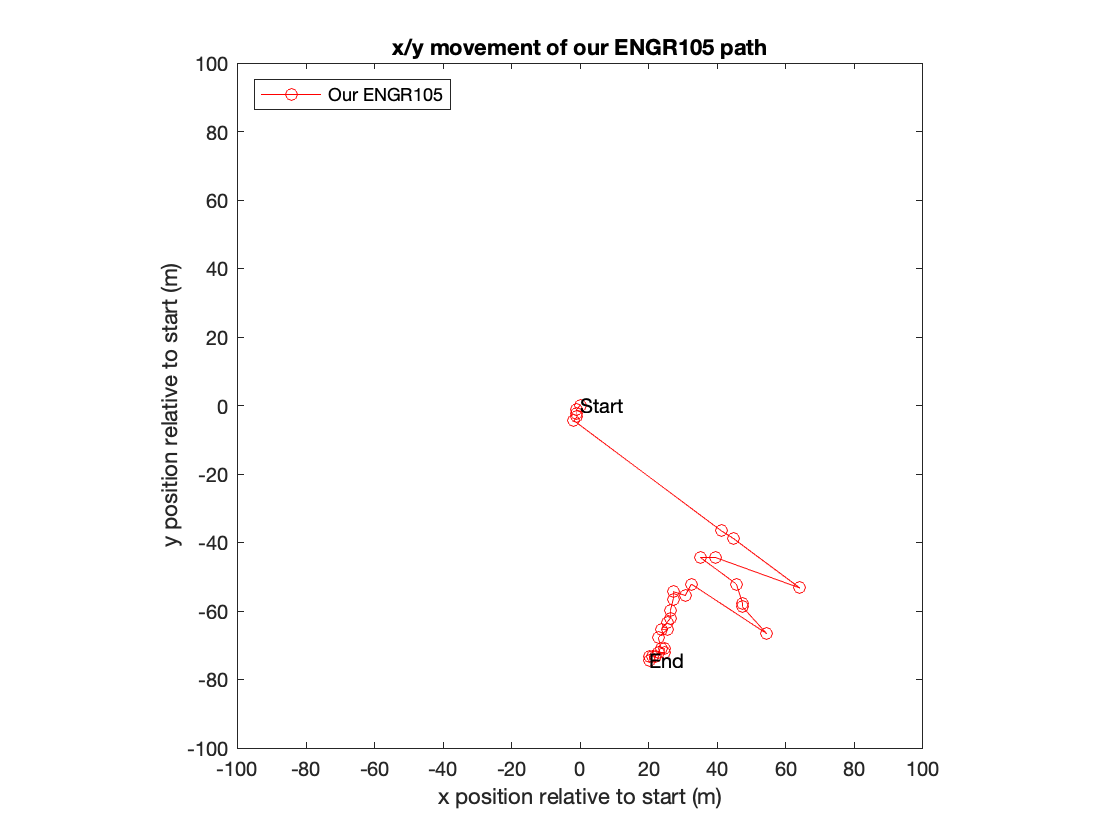

% Display figure in its own window
set(gcf,'Visible','on');

#### Plots as objects

- Functions can be stored as **function handles**. 

- Plots and graphics are inherently stored as **graphic handles**.

While these are not technically the same thing, they are both ways to store (at least temporarily) and access something as/from an (*explicitly* or *implicitly* defined) variable.

**First go**: Characteristics of the plot may be modified by referring to the **current axes or figure -- the one that is active.**

- `gca`: get current axes

- `gcf`: get current figure

The following is an example of a "typical" figure produced in the command line or a script file.

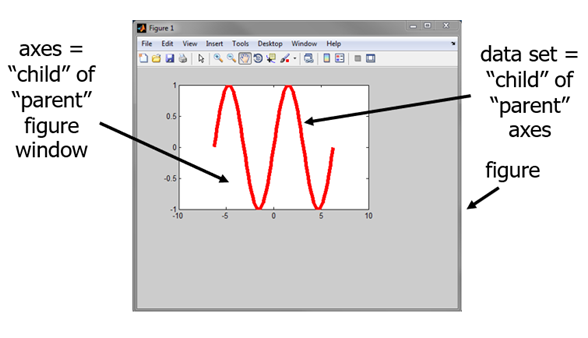

- A second plot command executed (without specifying `hold on`) will overwrite the axes from a first plot. 

**Important****: When working at the command line or in a .m file, new figures** can be created using the `figure` function, which will establish a new parent figure window. In a LiveScript document, **all figures are set to "not visible" by default and you see the axes**.

figure

When invoking the `axes()` command, MATLAB creates a "blank" set of axes. If invoked outside a LiveScript document, a new figure window will also be created to contain it.

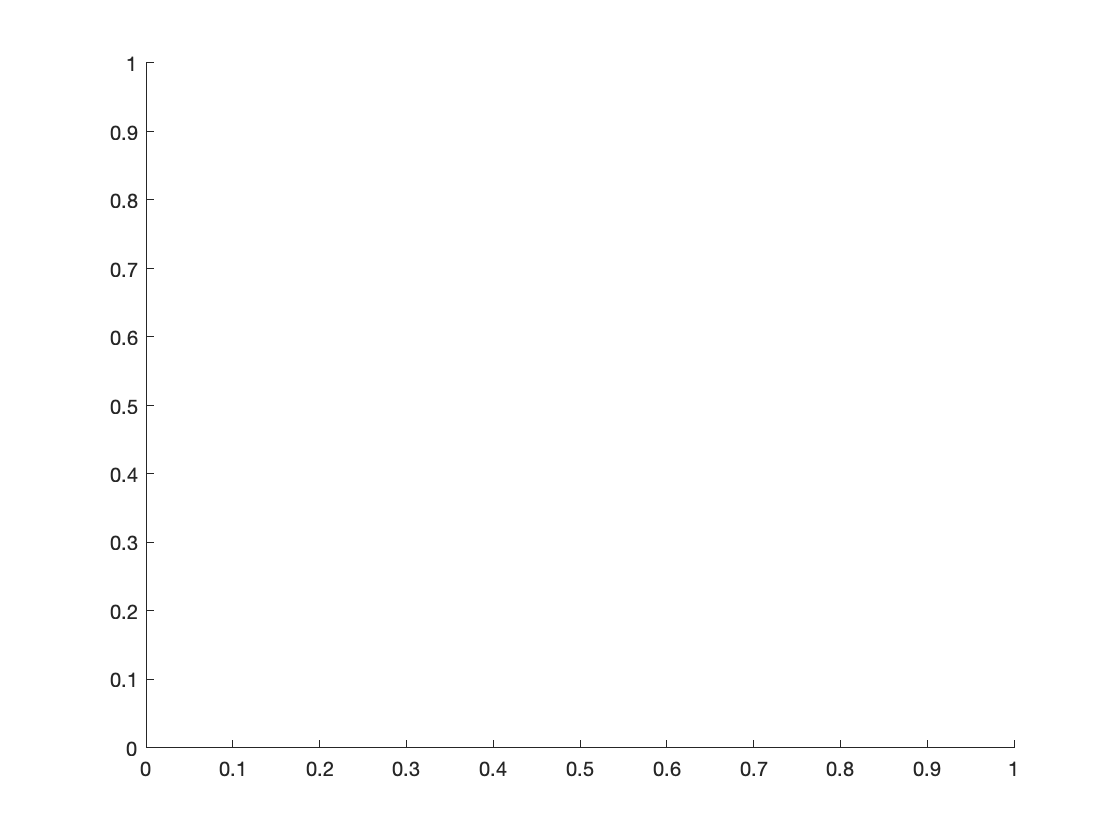

axes

#### Getting axes or figure properties

Current figure or axis parameters may be viewed by using the `get` function. **This is often a helpful way to understand what potential parameters may be modified.**

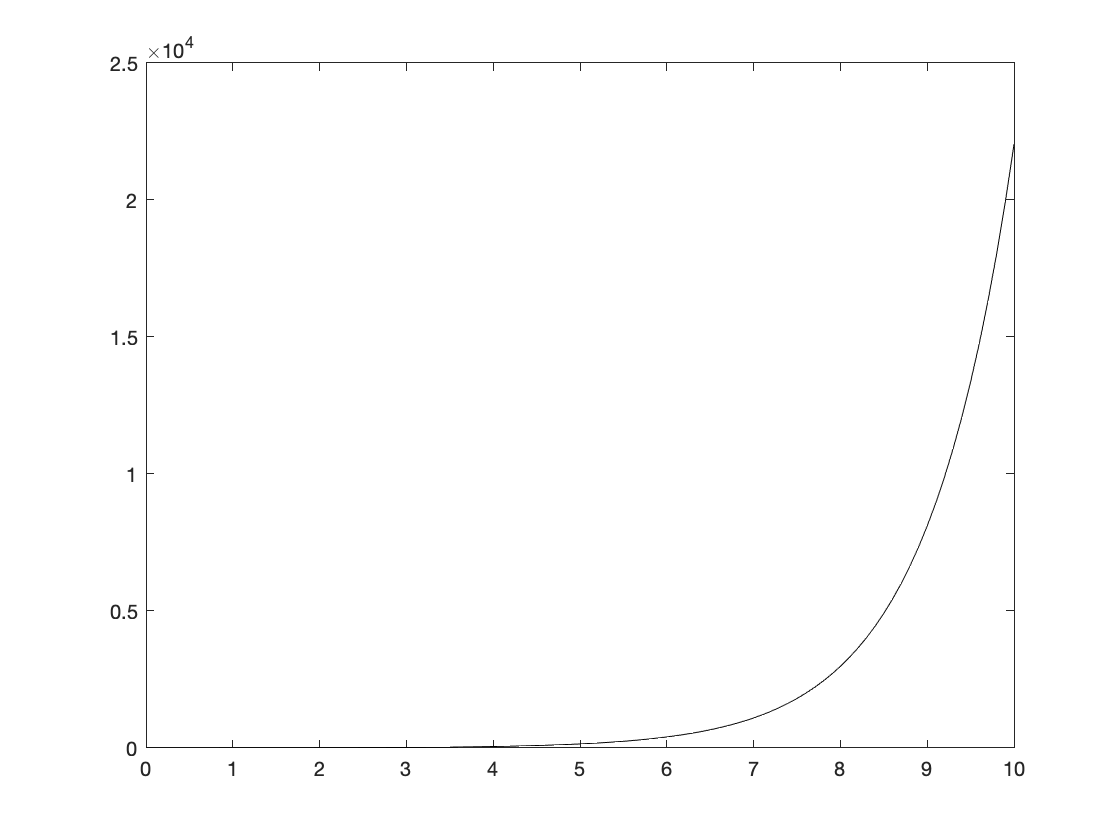

                        ALim: [0 1]
                    ALimMode: 'auto'
                  AlphaScale: 'linear'
                    Alphamap: [1×64 double]
           AmbientLightColor: [1 1 1]
                BeingDeleted: off
                         Box: on
                    BoxStyle: 'back'
                  BusyAction: 'queue'
               ButtonDownFcn: ''
                        CLim: [0 1]
                    CLimMode: 'auto'
              CameraPosition: [5 12500 17.3205]
          CameraPositionMode: 'auto'
                CameraTarget: [5 12500 0]
            CameraTargetMode: 'auto'
              CameraUpVector: [0 1 0]
          CameraUpVectorMode: 'auto'
             CameraViewAngle: 6.6086
         CameraViewAngleMode: 'auto'
                    Children: [1×1 Line]
                    Clipping: on
               ClippingStyle: '3dbox'
                       Color: [1 1 1]
                  ColorOrder: [7×3 double]
             ColorOrderIndex: 2
                  Co

% Create new plot of f(t) = exp(t)
t = 0:0.1:10;
f = exp(t);
plot(t,f,'k-')
get(gca)

#### Setting axes and figure properties

- `gca` or `gcf` may be combined with the `set` command to modify a plot characteristic.

- The general form for the `set` command is

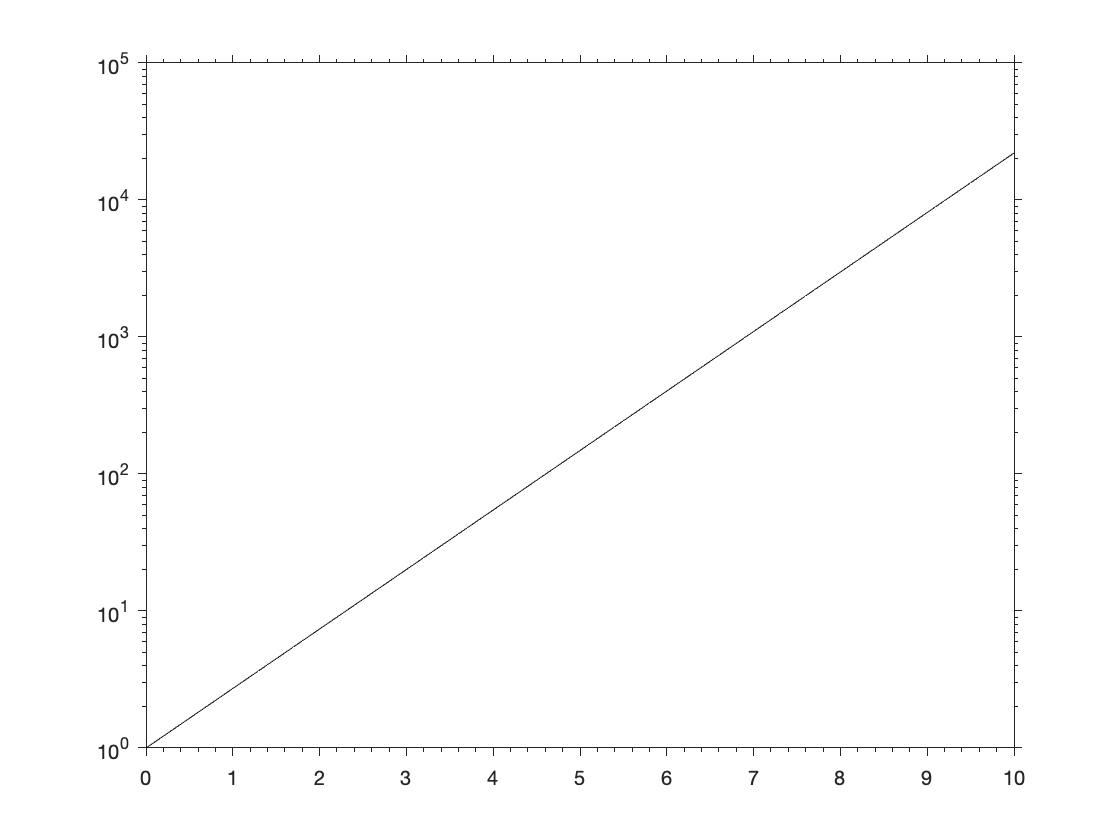

% Change some parameters
set(gca,'YScale','log')
set(gca,'XMinorTic','on')
set(gca,'TickDir','out')

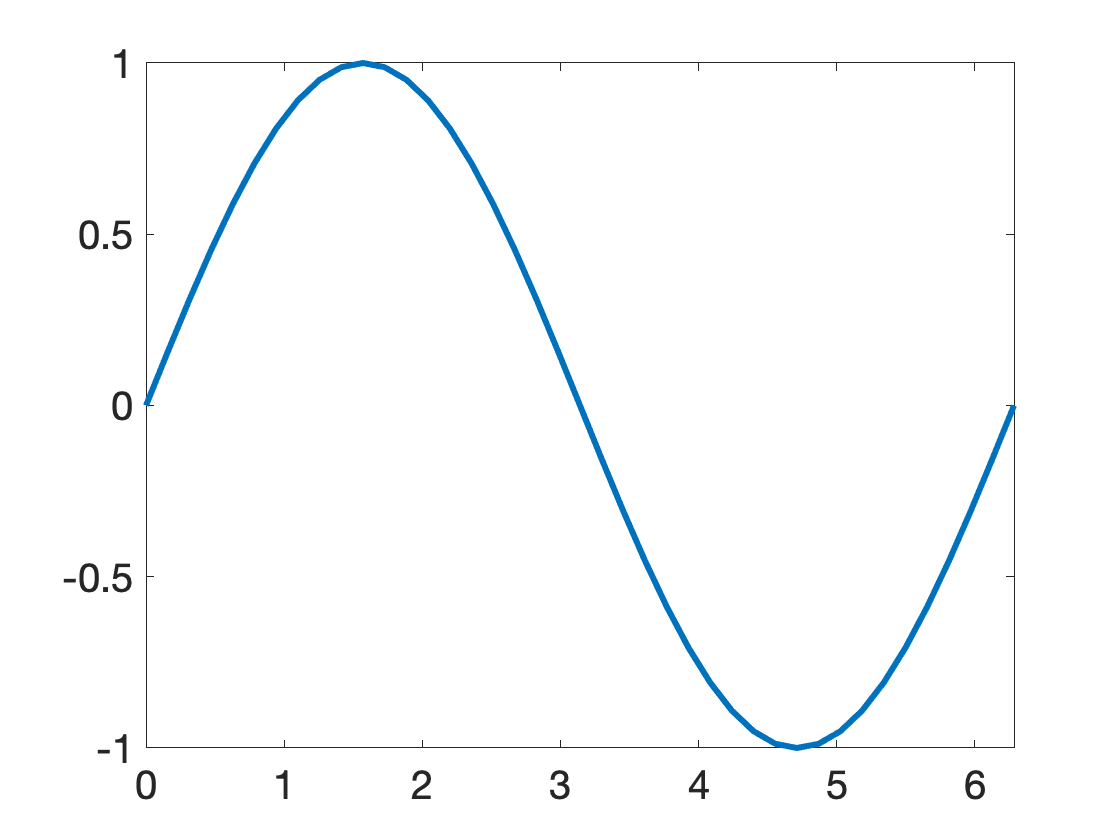

x = 0:pi/20:2*pi;
y = sin(x);
plot(x,y,'LineWidth',3)
% Increase the font size of the figure
set(gca,'FontSize',20)

**Note**: the plot that was produced most recently or is active is stored as `gca` or `gcf`. In the above case, `set` operates on that set of axes.

#### Graphics handles

In the same way that we created function handles to store functions in a variable, you can **create graphics handles** to store graphics in a variable.

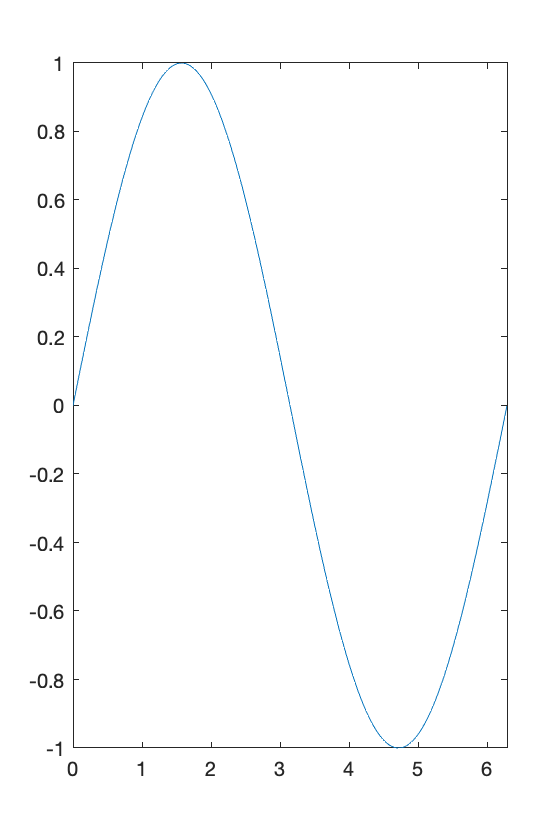

% Example graphics handle use
x = 0:pi/100:2*pi;
y = sin(x);
 
myFigure = figure;
plot(x,y)

% Set the background of the figure 
% to white
set(myFigure,'Color','w')
 
% Take the default plot position and 
% reduce the width by 1/2
pos = get(myFigure,'Position');
pos(3) = 0.5*pos(3);
set(myFigure,'Position',pos);

**Question 1: **my legend / plot / graphics object isn't working. What do I do?

- **Step 1**: Double check code for errors

- **Step 2**: Close all graphics objects and figures (`close all`)

- **Step 3**: consult documentation and Google (mathworks Q/A)

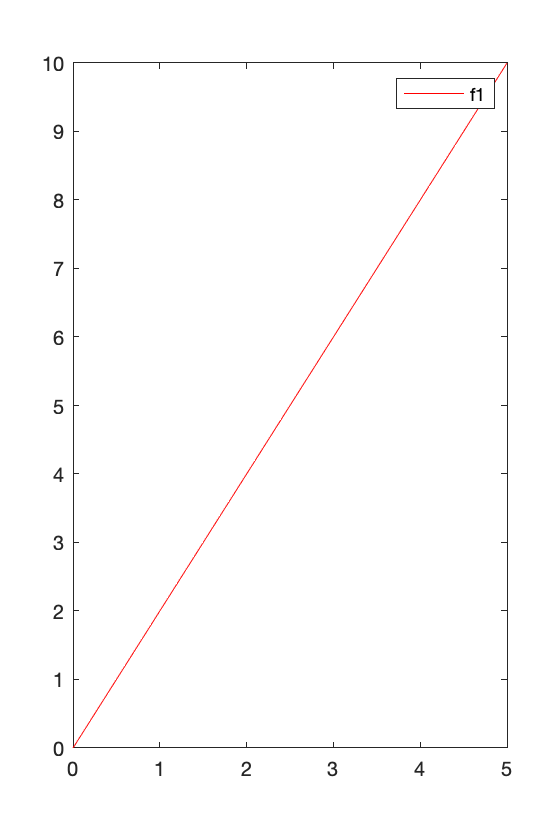

% This is the "usual" way we have added legends
t = 0:0.1:5;
f1 = 2*t;
f2 = t.^2;
plot(t,f1,'r-')
legend('f1')

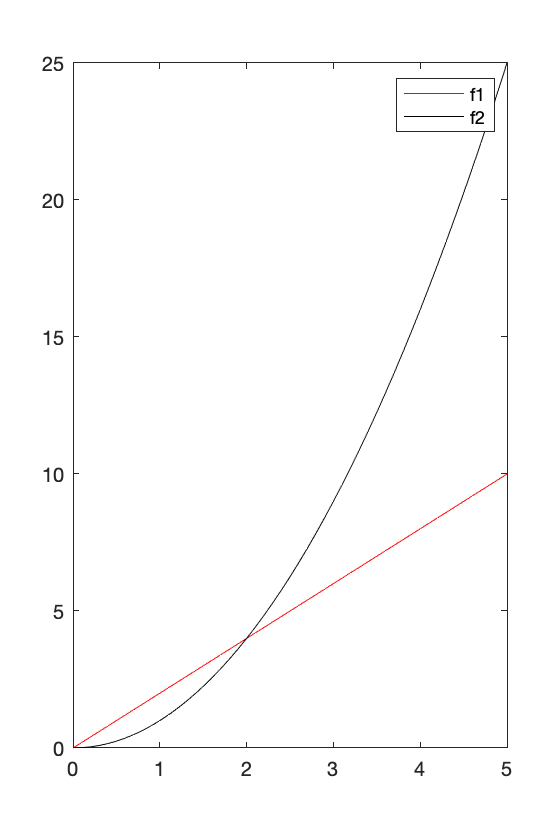

% Create graphics handles
h1 = plot(t,f1,'r-');
hold on
h2 = plot(t,f2,'k-');
hold off

% Create a legend by inputting. NOTE: this will change handle properties in
% h1 and h2!
h3 = legend([h1 h2],{'f1','f2'});

% Modify the the handle associated with each plot
plot(t,f1,'r-', 'DisplayName', 'f1');
hold on
plot(t,f2,'k-','DisplayName','f2');
hold off
legend

**Takeaway****:** all of these are doing the same thing. If one doesn't work, try one of the alternatives.

**Question 2**: what happens when you specifiy a line spec for a plot?

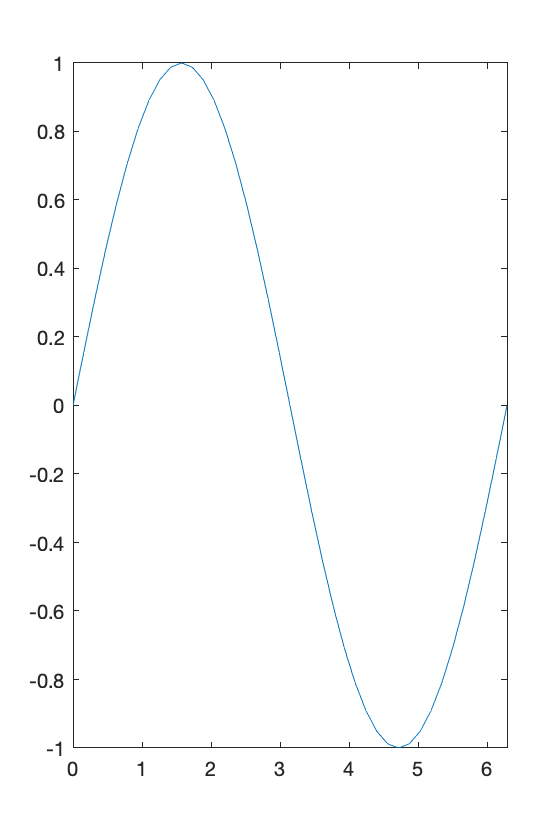

x = 0:pi/20:2*pi;
y = sin(x);
h1 = plot(x,y);

get(h1, 'LineWidth')

ans = 0.5000

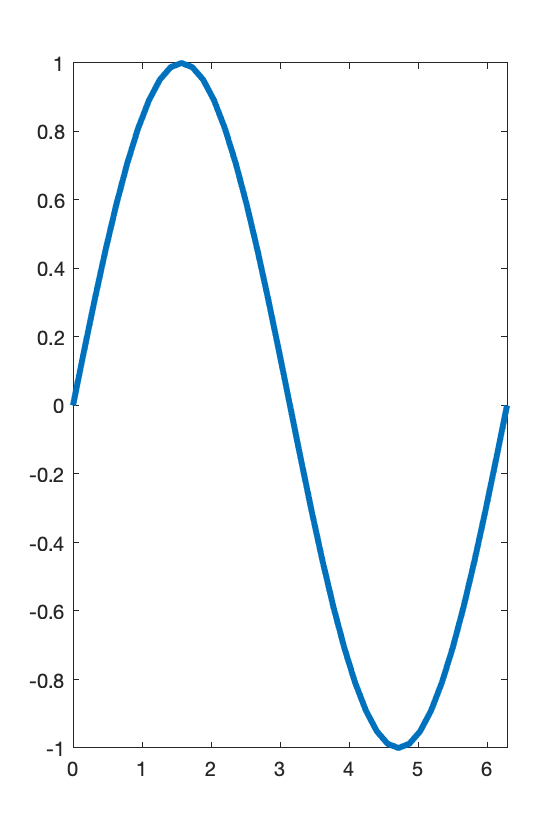

h2 = plot(x,y,'LineWidth',3);

get(h2, 'LineWidth')

ans = 3

**Specifiying a line specification or plotting option in the plot function is convenient for changing formatting perferences. It is equilavent to setting a field (parameter) for a graphics handle to a different value.**

#### Linear vs log axes

- Using `set` to **change axes properties**

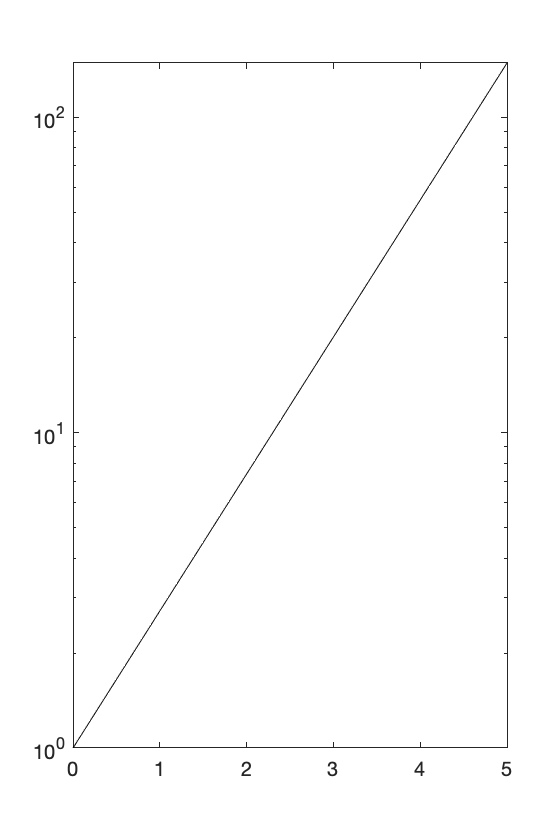

% Create new plot of f(t) = exp(t)
t = 0:0.1:5;
f = exp(t);
plot(t,f,'k-')
% Set y scale to logarithmic
set(gca,'YScale','log')

- **Logarithmic y axis**: `semilogy`

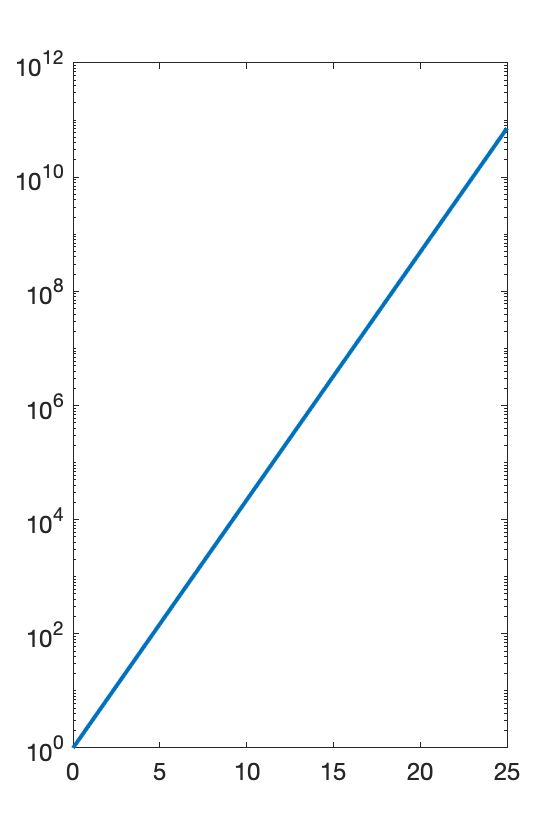

% x and y values
x = 0:1:25;
y = exp(x);

% Plot: y axis will have logarithmic scale 
p = semilogy(x,y);
% Change the line width
set(p,'LineWidth',2)
set(p,'LineWidth',2)
set(gca,'FontSize',12)

**Note**: line parameters can be changed using set, as above, **OR** by specifying line specification into plotting function.

- **Logarithmic x axis**: `semilogx`

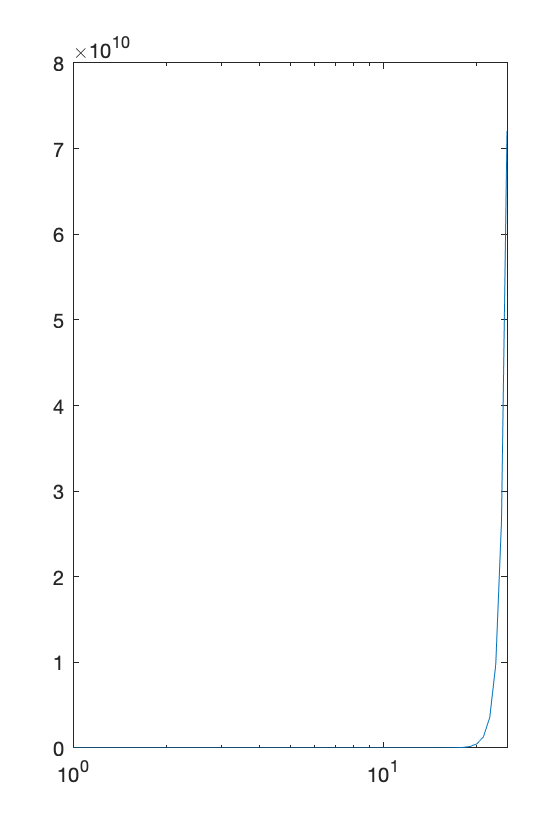

% Plot: y axis will have logarithmic scale 
p = semilogx(x,y);

- **Log-log plot**: `loglog`

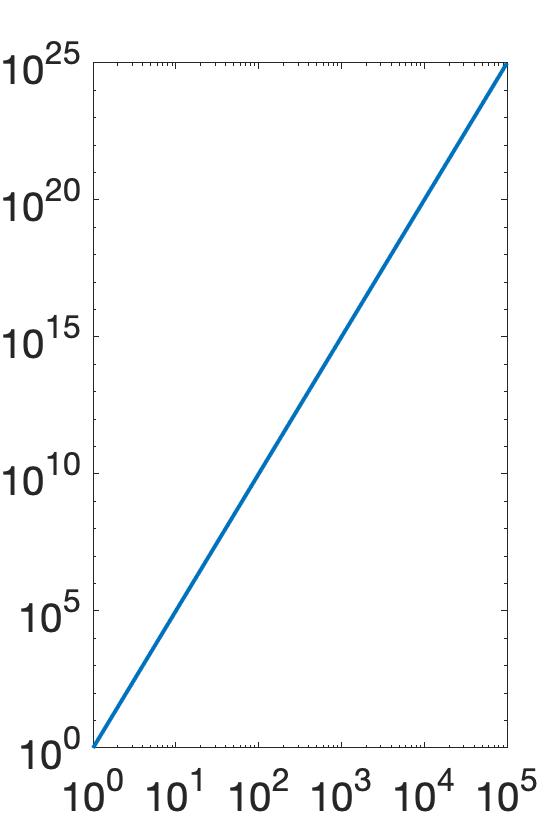

x = logspace(0,5,25);
y = x.^5;
p = loglog(x,y);
 
set(p,'LineWidth',2)
set(gca,'FontSize',20)
set(gca,'XTick',logspace(0,5,6))

#### Error bars

- **Y error bars**: use `errorbar` plotting function

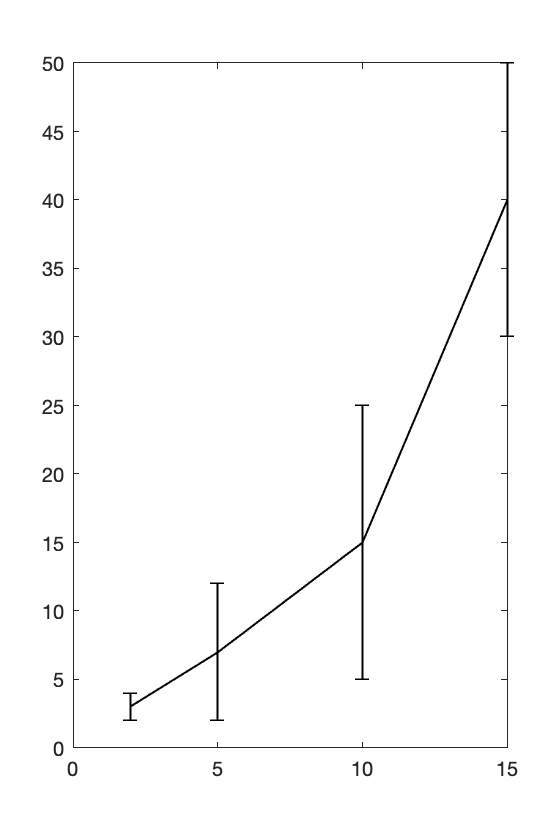

% Data values
x = [2,5,10,15];
y = [3,7,15,40];

% Y error bars: positive and negative are same
ye = [1,5,10,10];

% Graphics handle representing error bar plot function
h = errorbar(x,y,ye,'k-');
set(h,'LineWidth',1)

**Example**. How can we change error bar line properties and not the "data" line?

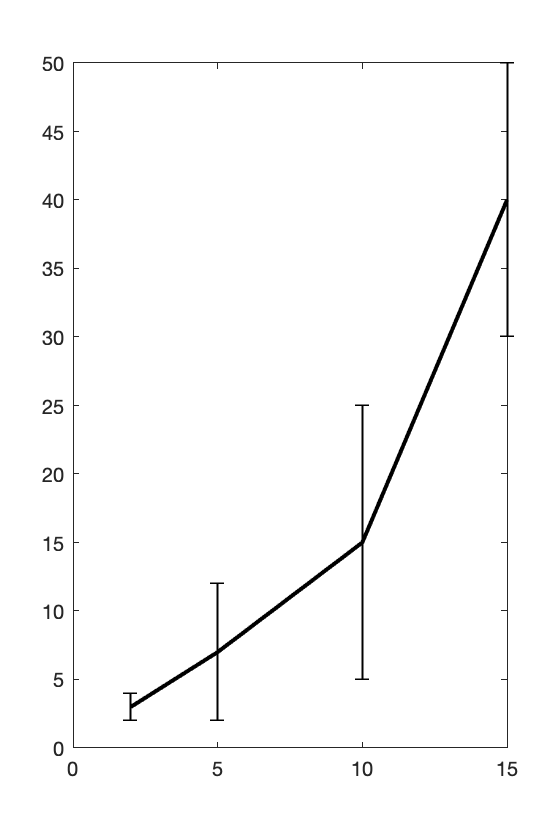

% Graphics handle representing error bar plot function
h = errorbar(x,y,ye,'k.','Marker','none');
hold on
plot(x,y,'k-','LineWidth',2)
hold off
% Change the parameters *ONLY* of the error bars
set(h,'LineWidth',1)

- **Y and X error bars**

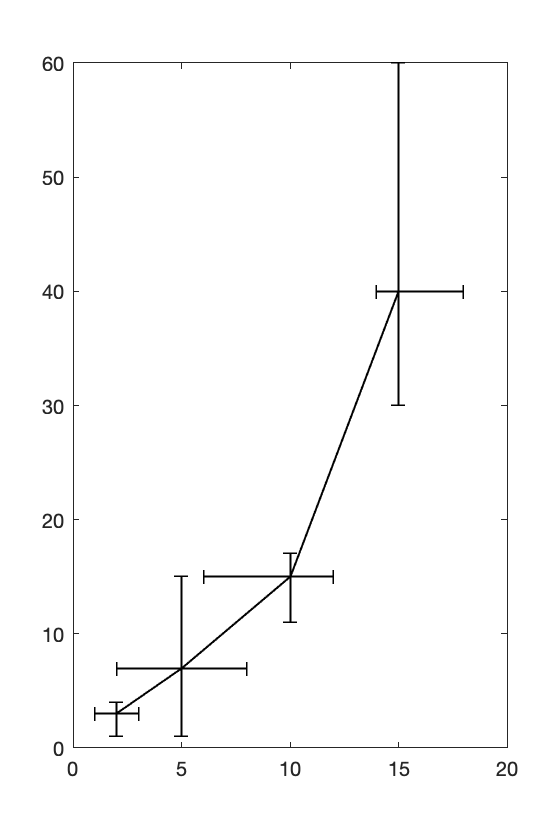

% Data values
x = [2,5,10,15];
y = [3,7,15,40];
 
% Positive and negative x error bars
xePos = [1,3,2,3];
xeNeg = [1,3,4,1];

% Positive and negative y error bars
yePos = [1,8,2,20];
yeNeg = [2,6,4,10];

% Create x and y error bar plot
h = errorbar(x,y,yeNeg,yePos,xeNeg,xePos,'k-');
set(h,'LineWidth',1)

#### Additional 2D plotting functions

- **Scatter plots. **Like plot, `scatter()`require vectors of equal length. the default plot attributes are circular blue data markers.

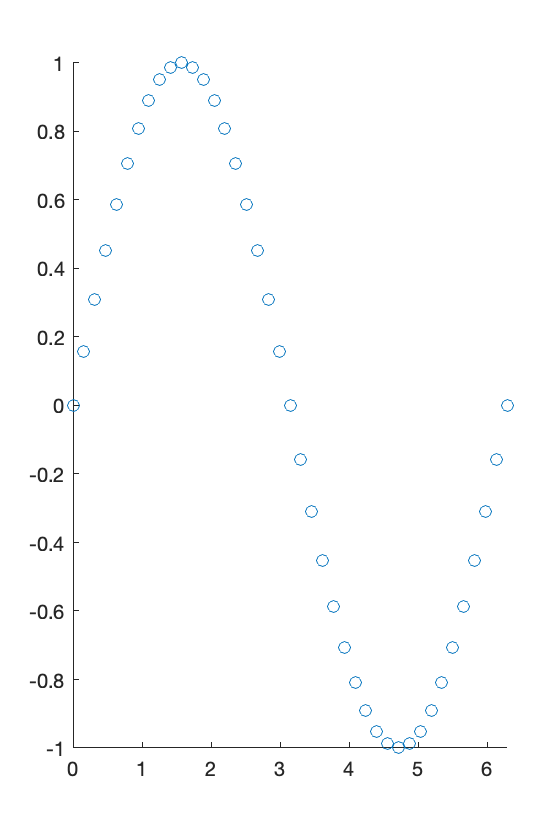

x = 0:pi/20:2*pi;
y = sin(x);
scatter(x,y)

- **Polarplot**

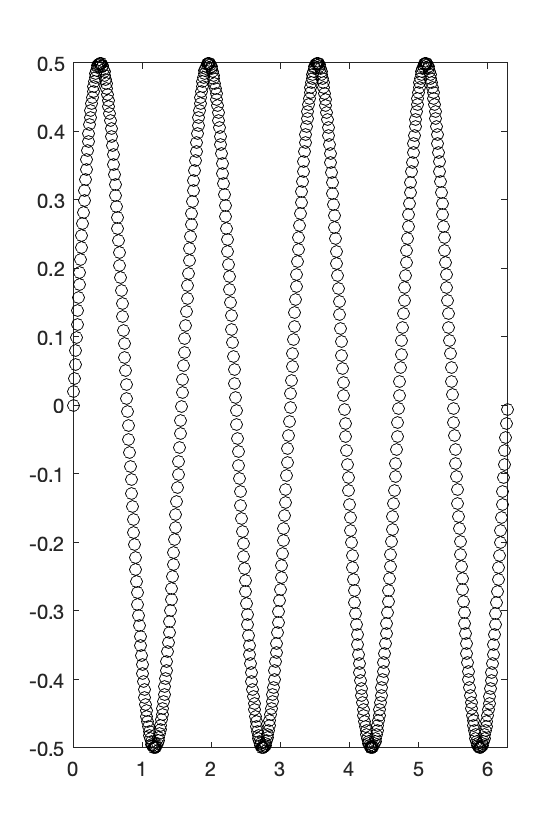

theta = 0:0.01:2*pi;
rho = sin(2*theta).*cos(2*theta);
% Plot theta vs. rho
plot(theta,rho,'ko')

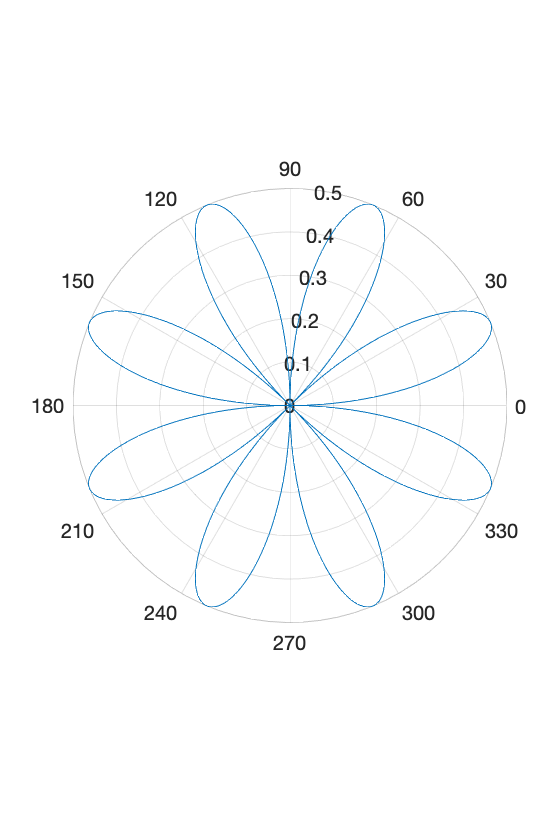

% Plot in polar space
polarplot(theta,rho)

**Note**: input is in units of radians.

- **histogram. **Display counts in different bins

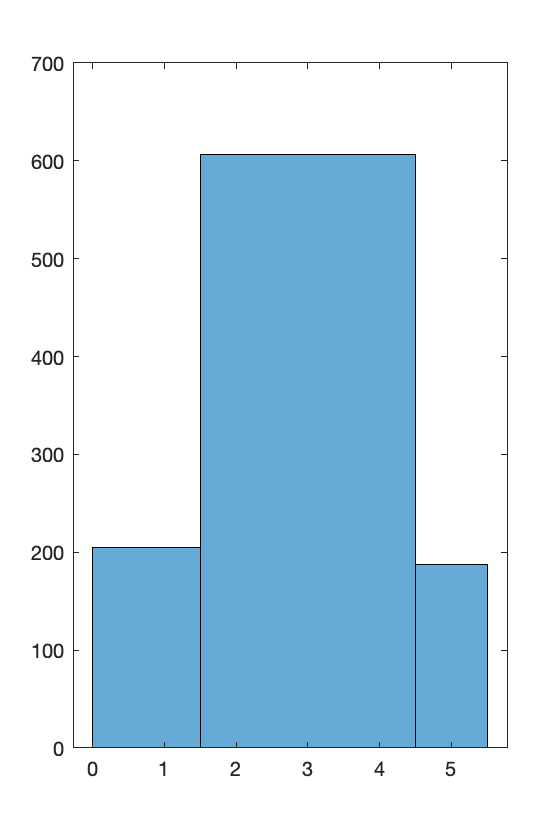

data = randi(5,[1,1000]);
h = histogram(data);
% Change bin sizes
set(h,'BinEdges',[0,1.5,4.5,5.5])

Back to our data. Create a histogram of speeds I traveled

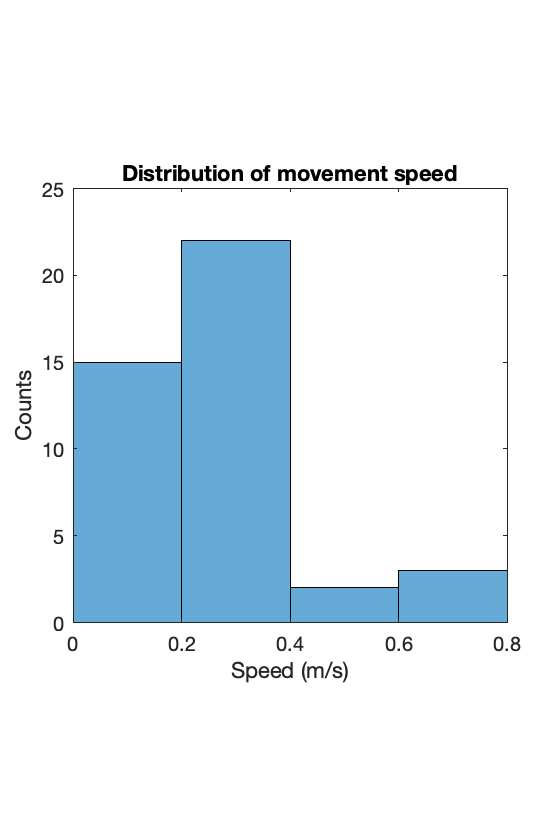

histogram(myData(:,5));
axis square
xlabel('Speed (m/s)')
ylabel('Counts')
title('Distribution of movement speed')

- **bar** plot

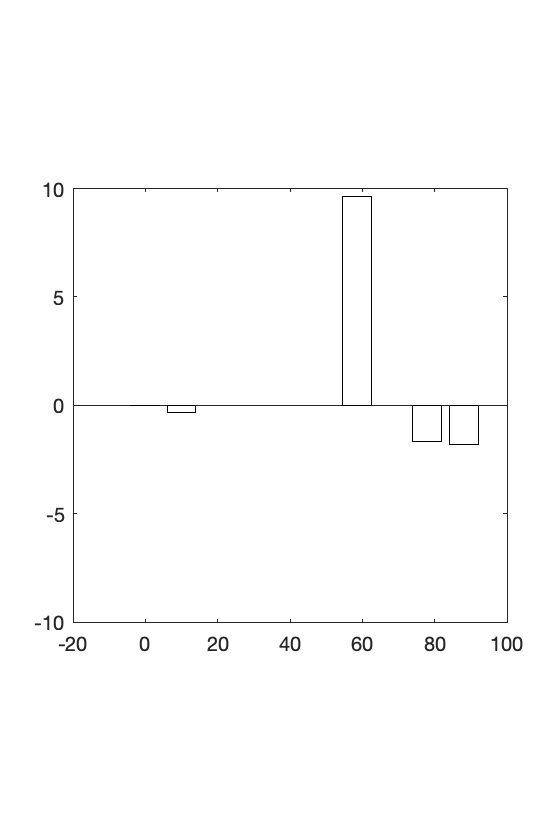

t = myData(1:10:end,1);
z = myData(1:10:end,4);

h = bar(t,z);
ylim([-10,10])
set(h,'FaceColor','none')
axis square

**Grouped bar plots**

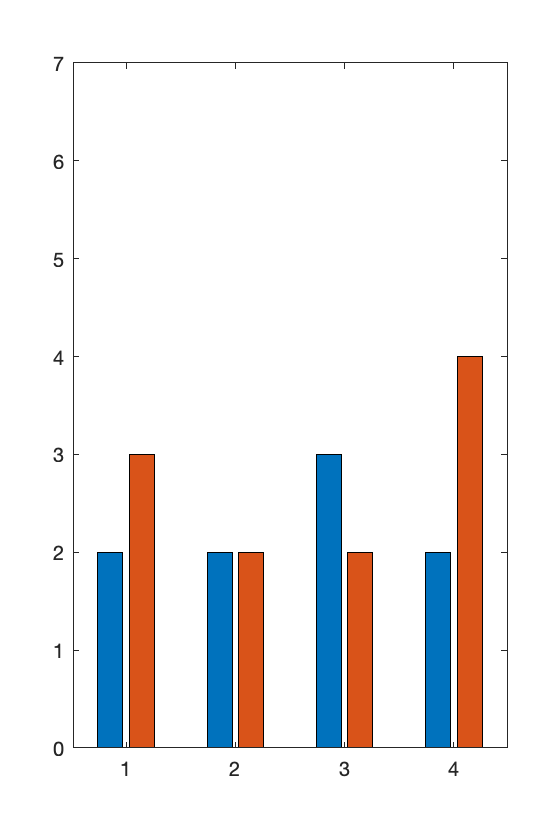

x = 1:4;
y1 = randi(3,[1,4]);
y2 = randi(5,[1,4]);
% Note: dimensions of "Y" input
h = bar(x,[y1;y2]');
ylim([0,7])

**Stacked bar plots**

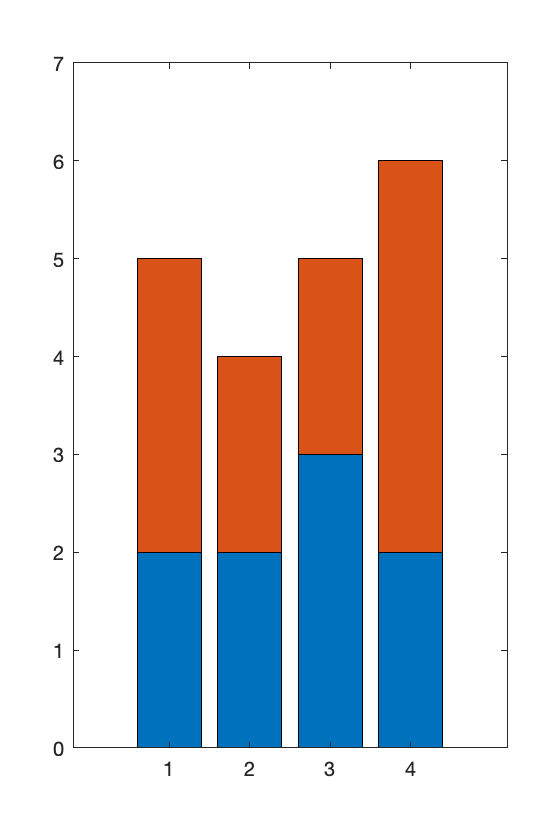

h = bar(x,[y1;y2]','stacked');
ylim([0,7])

#### Closing graphics objects -- SURPRISINGLY USEFUL

In an automated script, you may need to close figure windows. Figures may be closed using the `close` command

Sometimes when my figures are not responding correctly, I can fix the issue by closing all figure instances. The issue may be related to an open figure in the background. Figures, axes, and plots may also be assigned to handles and the handle specified to **close** the object.

f = figure;
plot(rand(1,20))
close(f)

#### Multiple axes in a single figure window

Multiple axes may be assigned to a single figure using the `subplot` command. This command has the following syntax:

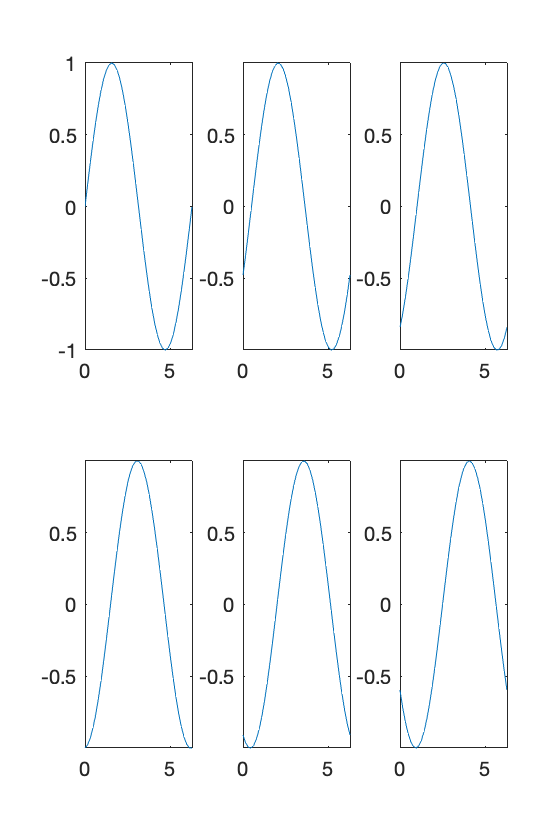

% X values
x = 0:pi/20:2*pi;

% Separate Y functions
y1 = sin(x-0);
y2 = sin(x-.5);
y3 = sin(x-1);
y4 = sin(x-1.5);
y5 = sin(x-2);
y6 = sin(x-2.5);
 
subplot(2,3,1)
plot(x,y1)
axis tight
 
subplot(2,3,2)
plot(x,y2)
axis tight

subplot(2,3,3)
plot(x,y3)
axis tight
 
subplot(2,3,4)
plot(x,y4)
axis tight
 
subplot(2,3,5)
plot(x,y5)
axis tight
 
subplot(2,3,6)
plot(x,y6)
axis tight

**Question**. How can this code be made **clearer**? Use a `for` loop -- we know how many iterations to perform

% X values
x = 0:pi/20:2*pi;

% For each loop iteration, fill in one of the subplots
for k = 0:5
    y = sin(x-0.5*k);
    
    subplot(2,3,k+1)
    plot(x,y)
    axis tight
end

### Plotting in 3D

All of the same concepts apply to producing 3D plots. In this case, the workhorse plot function is `plot3.`

#### `plot3`

plot3 takes in 3 inputs corresponding to x, y, and z positions

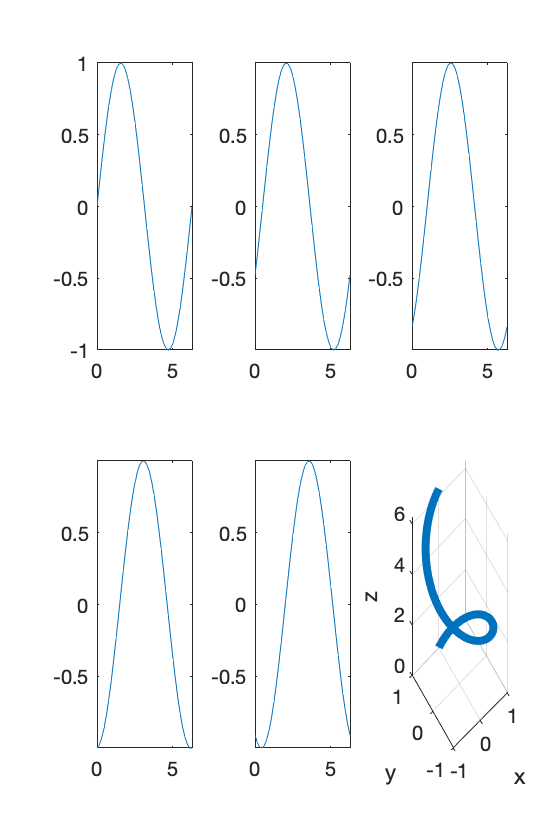

t = 0:pi/100:2*pi;
x = sin(t);
y = cos(t);
z = t;
plot3(x,y,z,'LineWidth',4)
xlabel('x')
ylabel('y')
zlabel('z')
grid on

**Note**: you can manually change the view point by clicking and dragging on the plot.

**Important note**: it is strongly recommended to specify a view point using `view`. This will help you precisely pick an angle to view.

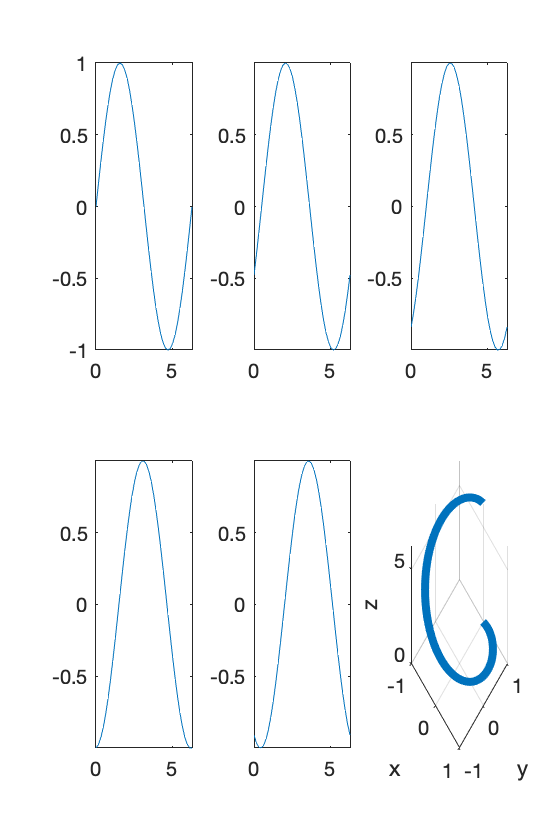

% Change the viewpoint
view(45,45)

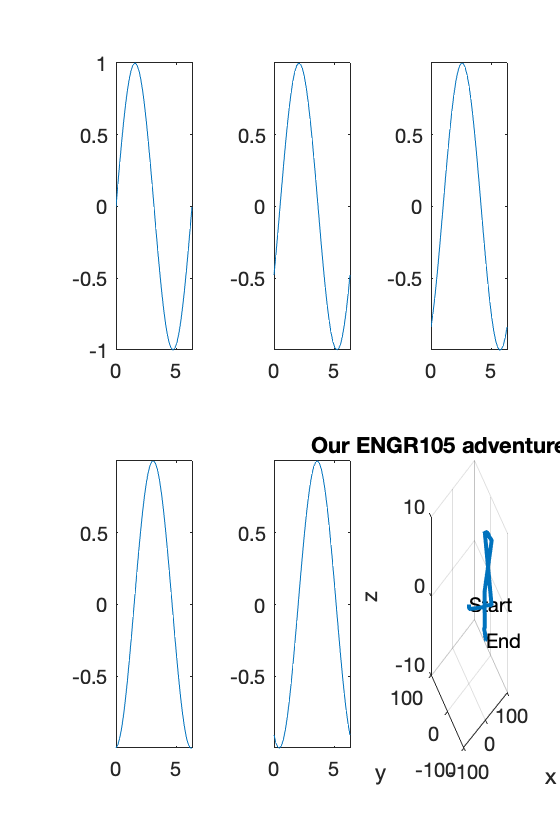

plot3(myData(:,2),myData(:,3),myData(:,4),'LineWidth',2)
xlabel('x')
ylabel('y')
zlabel('z')
xlim([-100,100])
ylim([-100,100])
zlim([-10,10])
grid on
title('Our ENGR105 adventure in 3D')
text(myData(1,2),myData(1,3),myData(1,4),'Start')
text(myData(end,2),myData(end,3),myData(end,4),'End')

#### Practice Problem: adventure summary

Produce one figure that summarizes the walk. That is, it should contain:

- Travel in 3D space

- x vs. y travel

- altitude as a function of time

- distribution of walking speeds

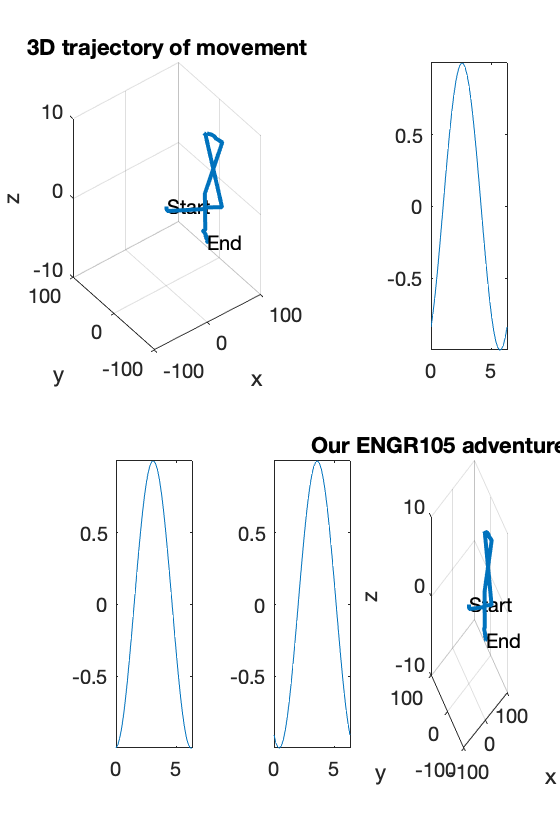

% Subplot 1: Travel in 3D
subplot(2,2,1)
plot3(myData(:,2), myData(:,3), myData(:,4), 'LineWidth', 2)
xlabel('x')
ylabel('y')
zlabel('z')
xlim([-100,100])
ylim([-100,100])
zlim([-10,10])
grid on
title('3D trajectory of movement')
text(myData(1,2), myData(1,3),myData(1,4),'Start')
text(myData(end,2), myData(end,3),myData(end,4),'End')

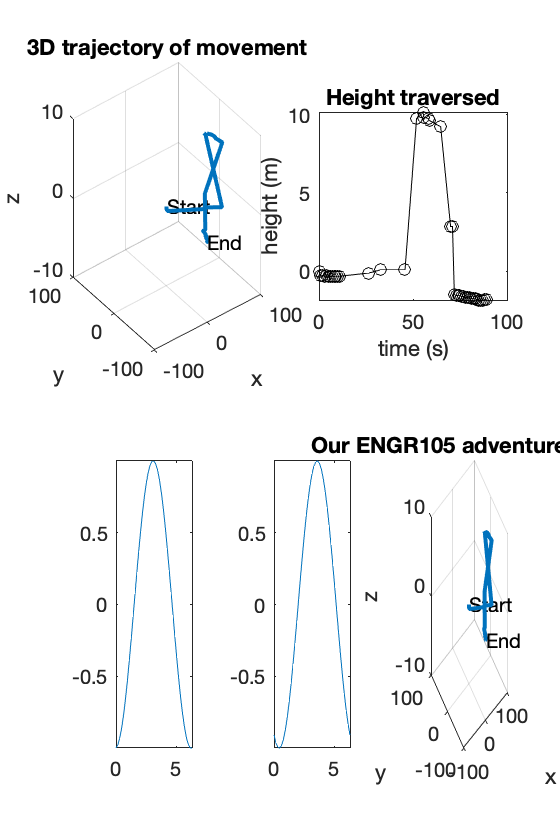


% Subplot 2: altitude as a function of time
subplot(2,2,2)
plot(myData(:,1), myData(:,4), 'ko-')
zlim([-10,10])
title('Height traversed')
xlabel('time (s)')
ylabel('height (m)')
axis square

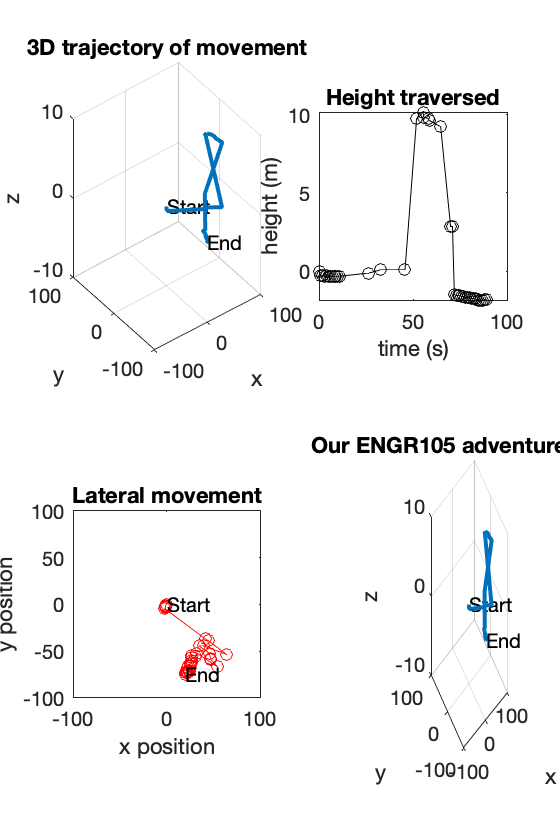



% Subplot 3: x vs y position
subplot(2,2,3)
plot(myData(:,2), myData(:,3), 'ro-')
xlabel('x position')
ylabel('y position')
xlim([-100,100])
ylim([-100,100])
axis square
title('Lateral movement')
text(myData(1,2), myData(1,3), 'Start')
text(myData(end,2), myData(end,3), 'End')

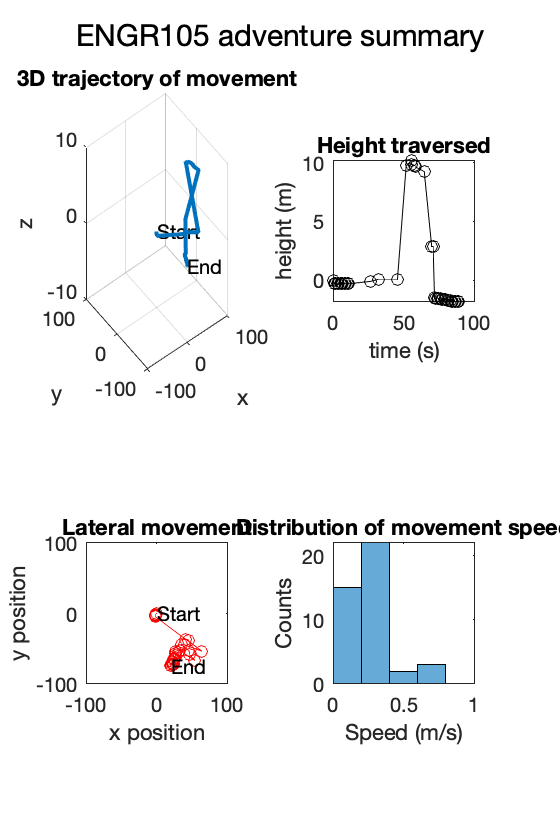



% Subplot 4: histogram of speeds
subplot(2,2,4)
histogram(myData(:,5));
axis square
xlabel('Speed (m/s)')
ylabel('Counts')
title('Distribution of movement speed')

% Add a title to the entire figure
sgtitle('ENGR105 adventure summary')